# Machine Learning: Programming Exercise 5

## Regularized Linear Regression and Bias vs. Variance

In this exercise, you will implement regularized linear regression and use it to study models with different bias-variance properties.

### Files needed for this exercise

- `ex5.mlx` - MATLAB Live Script that steps you through the exercise

- `ex5data1.mat` - Dataset

- `submit.m` - Submission script that sends your solutions to our servers

- `featureNormalize.m` - Feature normalization function

- `fmincg.m` - Function minimization routine (similar to `fminunc`)

- `plotFit.m` - Plot a polynomial fit

- `trainLinearReg.m` - Trains linear regression using your cost function

- *`linearRegCostFunction.m` - Regularized linear regression cost function

- `*learningCurve.m` - Generates a learning curve

- *`polyFeatures.m` - Maps data into polynomial feature space

- *`validationCurve.m` - Generates a cross validation curve

****indicates files you will need to complete***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex5' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Regularized Linear Regression

In the first half of the exercise, you will implement regularized linear regression to predict the amount of water flowing out of a dam using the change of water level in a reservoir. In the next half, you will go through some diagnostics of debugging learning algorithms and examine the effects of bias vs. variance.

### 1.1 Visualizing the dataset

We will begin by visualizing the dataset containing historical records on the change in the water level, $x$, and the amount of water flowing out of the dam, $y$. This dataset is divided into three parts:

- A **training** set that your model will learn on: `X, y`

- A **cross validation** set for determining the regularization parameter: `Xval, yval`

- A **test** set for evaluating performance. These are 'unseen' examples which your model did not see during training:` Xtest, ytest`

The code below will plot the training data (Figure 1). In the following parts, you will implement linear regression and use that to fit a straight line to the data and plot learning curves. Following that, you will implement polynomial regression to find a better fit to the data.

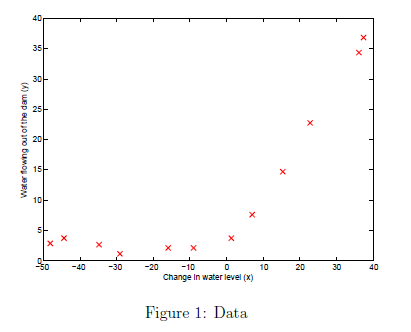

% Load from ex5data1: 
% You will have X, y, Xval, yval, Xtest, ytest in your environment
load ('ex5data1.mat');
% m = Number of examples
m = size(X, 1);

% Plot training data
figure;

plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');

### 1.2 Regularized linear regression cost function

Recall that regularized linear regression has the following cost function:


$$J\left(\theta \right)=\frac{1}{2m}\left(\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \right)+\frac{\;\lambda }{2m}\left(\sum_{j=1}^n \theta_j^2 \right)$$


where $\lambda$ is a regularization parameter which controls the degree of regularization (thus, helps preventing overfitting). The regularization term puts a penalty on the overall cost $J$. As the magnitudes of the model parameters $\theta_j$ increase, the penalty increases as well. Note that you should not regularize the $\theta_0$ term. (In MATLAB, the $\theta_0$ term is represented as `theta(1)` since indexing in MATLAB starts from 1).

    You should now complete the code in the file `linearRegCostFunction.m`. Your task is to write a function to calculate the regularized linear regression cost function. If possible, try to vectorize your code and avoid writing loops. When you are finished, the code below will run your cost function using `theta` initialized at `[1; 1]`. You should expect to see an output of 303.993.

theta = [1 ; 1];
J = linearRegCostFunction([ones(m, 1) X], y, theta, 1);

grad =   -15.3030
  598.2507


fprintf('Cost at theta = [1 ; 1]: %f', J);

Cost at theta = [1 ; 1]: 303.993192

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.3 Regularized linear regression gradient

Correspondingly, the partial derivative of regularized linear regression's cost for $\theta_j$ is defined as


$$\begin{array}{l}
\frac{\partial J\left(\theta \right)}{\partial \theta_0 }=\frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x^{\left(i\right)} \;\;\textrm{for}\;\;j=0\\
\frac{\partial J\left(\theta \right)}{\partial \theta_j }=\left(\frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \right)+\frac{\lambda }{m}\theta_j \;\;\;\textrm{for}\;\;j>0
\end{array}$$


In `linearRegCostFunction.m`, add code to calculate the gradient, returning it in the variable `grad`. When you are finished, the code below will run your gradient function using theta initialized at [1; 1]. You should expect to see a gradient of [-15.30; 598.250].

[J, grad] = linearRegCostFunction([ones(m, 1) X], y, theta, 1);

grad =   -15.3030
  598.2507


fprintf('Gradient at theta = [1 ; 1]:  [%f; %f] \n',grad(1), grad(2));

Gradient at theta = [1 ; 1]:  [-15.303016; 598.250744] 


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.4 Fitting linear regression

Once your cost function and gradient are working correctly, the code in this section will run the code in `trainLinearReg.m` to compute the optimal values of $\theta$. This training function uses `fmincg` to optimize the cost function. In this part, we set regularization parameter $\lambda$ to zero. Because our current implementation of linear regression is trying to fit a 2-dimensional $\theta$, regularization will not be incredibly helpful for a $\theta$ of such low dimension. In the later parts of the exercise, you will be using polynomial regression with regularization.

%  Train linear regression with lambda = 0
lambda = 0;
[theta] = trainLinearReg([ones(m, 1) X], y, lambda);

grad =   -11.2176
 -245.6520


grad =   -11.2381
 -242.2045


grad =   -11.2790
 -235.3094


grad =   -11.4018
 -214.6242


grad =   -11.7704
 -152.5687


grad =   -12.6798
    0.5790


Iteration     1 | Cost: 1.052435e+02


grad =   -11.2240
    0.5125


grad =    -8.3124
    0.3796


grad = 1.0e-10 *

   -0.0054
    0.4237


Iteration     2 | Cost: 2.237391e+01


grad = 1.0e-05 *

    0.0022
   -0.3700


grad = 1.0e-06 *

    0.0022
   -0.3700


grad = 1.0e-07 *

    0.0022
   -0.3696


grad = 1.0e-07 *

    0.0020
   -0.3326


grad = 1.0e-08 *

    0.0019
   -0.3288


grad = 1.0e-08 *

    0.0013
   -0.2170


grad = 1.0e-08 *

    0.0008
   -0.1426


grad = 1.0e-09 *

    0.0052
   -0.9290


grad = 1.0e-09 *

    0.0033
   -0.5977


grad = 1.0e-10 *

   -0.0016
   -0.2166


grad = 1.0e-10 *

   -0.0038
    0.1520


Iteration     3 | Cost: 2.237391e+01


grad = 1.0e-10 *

    0.0009
   -0.6040


grad = 1.0e-11 *

   -0.0333
    0.7639


grad = 1.0e-10 *

   -0.0038
    0.1443


grad = 1.0e-10 *

   -0.0038
    0.1507


grad = 1.0e-10 *

   -0.0038
    0.1477


grad = 1.0e-10 *

   -0.0038
    0.1504


grad = 1.0e-10 *

   -0.0038
    0.1488


grad = 1.0e-10 *

   -0.0038
    0.1481


grad = 1.0e-10 *

   -0.0038
    0.1477


grad = 1.0e-10 *

   -0.0038
    0.1481


grad = 1.0e-10 *

   -0.0038
    0.1481


grad = 1.0e-10 *

   -0.0038
    0.1481


grad = 1.0e-10 *

   -0.0038
    0.1481


grad = 1.0e-10 *

   -0.0038
    0.1481


grad = 1.0e-10 *

   -0.0038
    0.1481


grad = 1.0e-10 *

   -0.0038
    0.1481


grad = 1.0e-10 *

   -0.0038
    0.1481


grad = 1.0e-10 *

   -0.0038
    0.1481


grad = 1.0e-10 *

   -0.0038
    0.1481


grad = 1.0e-10 *

   -0.0038
    0.1481


grad = 1.0e-10 *

   -0.0038
    0.1481


grad = 1.0e-07 *

    0.0008
   -0.1256


grad = 1.0e-08 *

    0.0007
   -0.1242


grad = 1.0e-08 *

    0.0006
   -0.1117


grad = 1.0e-08 *

    0.0006
   -0.1003


grad = 1.0e-09 *

    0.0037
   -0.6614


grad = 1.0e-10 *

    0.0003
   -0.5255


grad = 1.0e-10 *

   -0.0013
   -0.2663


grad = 1.0e-10 *

   -0.0035
    0.1094


grad = 1.0e-11 *

   -0.0242
   -0.7839


grad = 2×1
1.0e-11 *

   -0.0302
    0.2273


Iteration     5 | Cost: 2.237391e+01


grad = 2×1
1.0e-10 *

   -0.0010
   -0.2799


grad = 2×1
1.0e-10 *

   -0.0017
   -0.1743


grad = 2×1
1.0e-12 *

   -0.2888
    0.3335


Iteration     6 | Cost: 2.237391e+01


grad = 2×1
1.0e-11 *

   -0.0230
   -0.8018


grad = 2×1
1.0e-12 *

   -0.2823
   -0.5391


grad = 2×1
1.0e-12 *

   -0.2866
    0.2198


grad = 2×1
1.0e-12 *

   -0.2850
   -0.1572


Iteration     7 | Cost: 2.237391e+01


grad = 2×1
1.0e-12 *

   -0.2832
   -0.0671


grad = 2×1
1.0e-12 *

   -0.2850
   -0.1572


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-10 *

   -0.0047
    0.7756


grad = 2×1
1.0e-11 *

   -0.0304
    0.7607


grad = 2×1
1.0e-12 *

   -0.2855
    0.6244


grad = 2×1
1.0e-12 *

   -0.2832
   -0.0671


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


    Finally, the code below should also plot the best fit line, resuling in an imagte similar to Figure 2. The best fit line tells us that the model is not a good fit to the data because the data has a nonlinear pattern. 

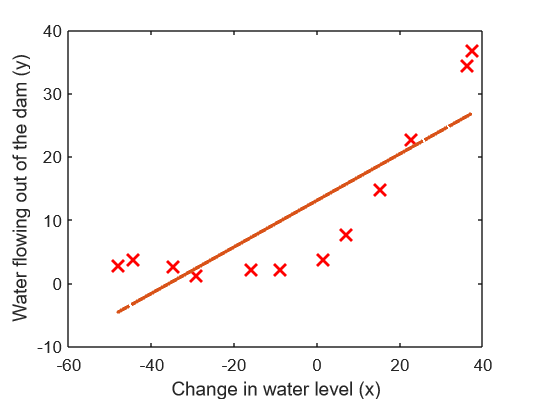

%  Plot fit over the data
figure;
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
hold on;
plot(X, [ones(m, 1) X]*theta, '--', 'LineWidth', 2)
hold off;

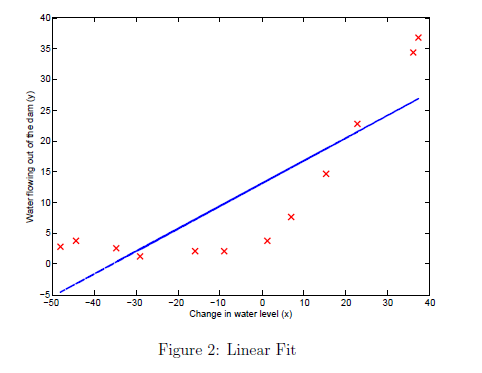

While visualizing the best fit as shown is one possible way to debug your learning algorithm, it is not always easy to visualize the data and model. In the next section, you will implement a function to generate learning curves that can help you debug your learning algorithm even if it is not easy to visualize the data.

## 2. Bias-variance

An important concept in machine learning is the bias-variance tradeoff. Models with high bias are not complex enough for the data and tend to underfit, while models with high variance overfit the training data. In this part of the exercise, you will plot training and test errors on a learning curve to diagnose bias-variance problems.

### 2.1 Learning curves

You will now implement code to generate the learning curves that will be useful in debugging learning algorithms. Recall that a learning curve plots training and cross validation error as a function of training set size. Your job is to fill in `learningCurve.m` so that it returns a vector of errors for the training set and cross validation set.

    To plot the learning curve, we need a training and cross validation set error for different training set sizes. To obtain different training set sizes, you should use different subsets of the original training set `X`. Specically, for a training set size of `i`, you should use the first `i` examples (i.e., `X(1:i,:) `and `y(1:i))`. You can use the `trainLinearReg` function to find the $\theta$ parameters. Note that `lambda` is passed as a parameter to the `learningCurve` function. After learning the $\theta$ parameters, you should compute the error on the training and cross validation sets. Recall that the training error for a dataset is defined as


$$J_{\textrm{train}} \left(\theta \right)=\frac{1}{2m}\left\lbrack \sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \right\rbrack$$


    In particular, note that the training error does not include the regularization term. One way to compute the training error is to use your existing cost function and set $\lambda$ to 0 only when using it to compute the training error and cross validation error. When you are computing the training set error, make sure you compute it on the training subset (i.e., `X(1:n,:)` and `y(1:n)`, instead of the entire training set). However, for the cross validation error, you should compute it over the entire cross validation set. You should store the computed errors in the vectors `error_train` and `error_val`.  

    In Figure 3, you can observe that both the train error and cross validation error are high when the number of training examples is increased. This reflects a high bias problem in the model - the linear regression model is too simple and is unable to fit our dataset well. In the next section, you will implement polynomial regression to fit a better model for this dataset.

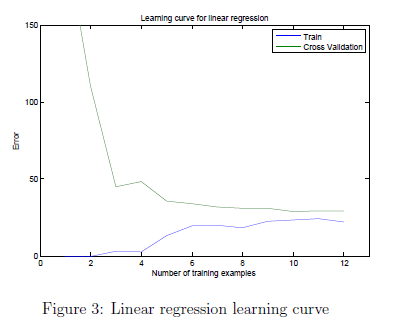

    When you are finished, run the code below to compute the learning curves and produce a plot similar to Figure 3.

lambda = 0;
[error_train, error_val] = learningCurve([ones(m, 1) X], y, [ones(size(Xval, 1), 1) Xval], yval, lambda);

grad =    -2.1343
   34.0140


grad =    -1.6662
   26.5535


grad =    -0.7299
   11.6325


Iteration     1 | Cost: 2.663868e-01


grad =     3.3766
  -53.8125


grad = 1.0e-13 *

   -0.0089
    0.1415


Iteration     2 | Cost: 3.944305e-31


grad = 1.0e-11 *

    0.0170
   -0.2704


grad = 1.0e-12 *

    0.0164
   -0.2619


grad = 1.0e-13 *

    0.0089
   -0.1415


grad =      0
     0


Iteration     3 | Cost: 0.000000e+00


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad =      0
     0


grad = 2×1
     0
     0


grad = 2×1
     0
     0


grad = 2×1
  -12.3370
 -367.6732


grad = 2×1
   -1.6538
   34.1090


grad = 2×1
   -0.9935
   17.9472


grad = 2×1
   -0.2598
   -0.0126


Iteration     1 | Cost: 4.282328e-01


grad = 2×1
   -0.2561
   -0.0124


grad = 2×1
   -0.2487
   -0.0121


grad = 2×1
   -0.2264
   -0.0110


grad = 2×1
   -0.1596
   -0.0077


grad = 2×1
1.0e-13 *

    0.0377
   -0.9537


Iteration     2 | Cost: 8.332343e-30


grad = 2×1
1.0e-07 *

   -0.0273
    0.6675


grad = 2×1
1.0e-08 *

   -0.0273
    0.6675


grad = 2×1
1.0e-09 *

   -0.0273
    0.6674


grad = 2×1
1.0e-10 *

   -0.0272
    0.6665


grad = 2×1
1.0e-11 *

   -0.0269
    0.6580


grad = 2×1
1.0e-12 *

   -0.0233
    0.5711


grad = 2×1
1.0e-14 *

         0
   -0.2935


Iteration     3 | Cost: 9.860761e-32


grad = 2×1
1.0e-14 *

   -0.0222
    0.3539


grad = 2×1
1.0e-14 *

   -0.0222
    0.3539


grad = 2×1
1.0e-14 *

   -0.0222
    0.3539


grad = 2×1
1.0e-14 *

   -0.0222
    0.3539


grad = 2×1
1.0e-14 *

   -0.0222
    0.3539


grad = 2×1
1.0e-14 *

   -0.0222
    0.3539


grad = 2×1
1.0e-14 *

   -0.0222
    0.3539


grad = 2×1
1.0e-14 *

   -0.0222
    0.3539


grad = 2×1
1.0e-14 *

   -0.0222
    0.3539


grad = 2×1
1.0e-14 *

   -0.0222
    0.3539


grad = 2×1
1.0e-14 *

   -0.0222
    0.3539


grad = 2×1
1.0e-14 *

   -0.0222
    0.3539


grad = 2×1
1.0e-14 *

   -0.0222
    0.3539


grad = 2×1
1.0e-14 *

   -0.0222
    0.3539


grad = 2×1
1.0e-14 *

   -0.0222
    0.3539


grad = 2×1
1.0e-14 *

   -0.0222
    0.3539


grad = 2×1
1.0e-14 *

   -0.0222
    0.3539


grad = 2×1
1.0e-14 *

   -0.0222
    0.3539


grad = 2×1
1.0e-14 *

   -0.0222
    0.3539


grad = 2×1
1.0e-14 *

   -0.0222
    0.3539


grad = 2×1
1.0e-14 *

   -0.0222
    0.3539


grad = 2×1
1.0e-11 *

    0.0080
   -0.1958


grad = 2×1
1.0e-12 *

    0.0082
   -0.2014


grad = 2×1
1.0e-13 *

    0.0111
   -0.2943


grad = 2×1
1.0e-13 *

    0.0044
   -0.1295


grad = 2×1
1.0e-13 *

    0.0044
   -0.1295


grad = 2×1
1.0e-13 *

    0.0044
   -0.1295


grad = 2×1
1.0e-13 *

    0.0044
   -0.1295


grad = 2×1
1.0e-13 *

    0.0044
   -0.1295


grad = 2×1
1.0e-13 *

    0.0044
   -0.1295


grad = 2×1
1.0e-13 *

    0.0044
   -0.1295


grad = 2×1
1.0e-13 *

    0.0044
   -0.1295


grad = 2×1
1.0e-13 *

    0.0044
   -0.1295


grad = 2×1
1.0e-13 *

    0.0044
   -0.1295


grad = 2×1
1.0e-13 *

    0.0044
   -0.1295


grad = 2×1
1.0e-13 *

    0.0044
   -0.1295


grad = 2×1
1.0e-13 *

    0.0044
   -0.1295


grad = 2×1
1.0e-13 *

    0.0044
   -0.1295


grad = 2×1
1.0e-13 *

    0.0044
   -0.1295


grad = 2×1
1.0e-13 *

    0.0044
   -0.1295


grad = 2×1
1.0e-13 *

    0.0044
   -0.1295


grad = 2×1
1.0e-13 *

    0.0044
   -0.1295


grad = 2×1
1.0e-14 *

         0
   -0.2935


grad = 2×1
   -9.9193
 -197.7035


grad = 2×1
  -12.5556
 -391.7409


grad = 2×1
  -12.5630
 -389.6896


grad = 2×1
  -12.5780
 -385.5869


grad = 2×1
  -12.6229
 -373.2788


grad = 2×1
  -12.7576
 -336.3547


grad = 2×1
  -13.1617
 -225.5823


grad = 2×1
  -13.9863
    0.4483


Iteration     1 | Cost: 1.021540e+02


grad = 2×1
  -12.2625
    0.3930


grad = 2×1
   -8.8149
    0.2825


grad = 2×1
1.0e-11 *

   -0.0406
    0.7180


Iteration     2 | Cost: 3.286595e+00


grad = 2×1
1.0e-06 *

    0.0021
   -0.5834


grad = 2×1
1.0e-07 *

    0.0021
   -0.5833


grad = 2×1
1.0e-08 *

    0.0021
   -0.5827


grad = 2×1
1.0e-08 *

    0.0019
   -0.5244


grad = 2×1
1.0e-09 *

    0.0015
   -0.5178


grad = 2×1
1.0e-10 *

   -0.0021
   -0.4535


grad = 2×1
1.0e-11 *

   -0.0386
    0.1947


grad = 2×1
1.0e-11 *

   -0.0403
    0.6679


grad = 2×1
1.0e-11 *

   -0.0395
    0.4334


grad = 2×1
1.0e-11 *

   -0.0402
    0.6501


grad = 2×1
1.0e-11 *

   -0.0402
    0.6501


grad = 2×1
1.0e-11 *

   -0.0399
    0.5421


grad = 2×1
1.0e-11 *

   -0.0403
    0.6388


grad = 2×1
1.0e-11 *

   -0.0402
    0.6501


grad = 2×1
1.0e-11 *

   -0.0403
    0.6388


grad = 2×1
1.0e-11 *

   -0.0403
    0.6388


grad = 2×1
1.0e-11 *

   -0.0403
    0.6388


grad = 2×1
1.0e-11 *

   -0.0403
    0.6388


grad = 2×1
1.0e-11 *

   -0.0403
    0.6388


grad = 2×1
1.0e-11 *

   -0.0403
    0.6388


grad = 2×1
1.0e-11 *

   -0.0403
    0.6388


grad = 2×1
1.0e-08 *

    0.0019
   -0.5133


grad = 2×1
1.0e-09 *

    0.0015
   -0.5068


grad = 2×1
1.0e-09 *

    0.0013
   -0.4555


grad = 2×1
1.0e-10 *

   -0.0023
   -0.3923


grad = 2×1
1.0e-11 *

   -0.0385
    0.2494


Iteration     4 | Cost: 3.286595e+00


grad = 2×1
1.0e-11 *

   -0.0341
   -0.8910


grad = 2×1
1.0e-11 *

   -0.0382
    0.1414


grad = 2×1
1.0e-11 *

   -0.0386
    0.2377


grad = 2×1
1.0e-11 *

   -0.0385
    0.2494


grad = 2×1
1.0e-11 *

   -0.0386
    0.2377


grad = 2×1
1.0e-11 *

   -0.0385
    0.2494


grad = 2×1
1.0e-11 *

   -0.0385
    0.2494


grad = 2×1
1.0e-11 *

   -0.0385
    0.2494


grad = 2×1
1.0e-11 *

   -0.0385
    0.2494


grad = 2×1
1.0e-11 *

   -0.0385
    0.2494


grad = 2×1
1.0e-11 *

   -0.0385
    0.2494


grad = 2×1
1.0e-11 *

   -0.0385
    0.2494


grad = 2×1
1.0e-11 *

   -0.0385
    0.2494


grad = 2×1
1.0e-11 *

   -0.0385
    0.2494


grad = 2×1
1.0e-11 *

   -0.0385
    0.2494


grad = 2×1
1.0e-11 *

   -0.0385
    0.2494


grad = 2×1
1.0e-11 *

   -0.0385
    0.2494


grad = 2×1
1.0e-11 *

   -0.0385
    0.2494


grad = 2×1
1.0e-11 *

   -0.0385
    0.2494


grad = 2×1
1.0e-11 *

   -0.0385
    0.2494


grad = 2×1
1.0e-11 *

   -0.0385
    0.2494


grad = 2×1
1.0e-08 *

    0.0007
   -0.2005


grad = 2×1
1.0e-09 *

    0.0004
   -0.1982


grad = 2×1
1.0e-10 *

   -0.0031
   -0.1751


grad = 2×1
1.0e-10 *

   -0.0032
   -0.1558


grad = 2×1
1.0e-11 *

   -0.0341
   -0.9059


grad = 2×1
1.0e-11 *

   -0.0346
   -0.7930


grad = 2×1
1.0e-11 *

   -0.0380
    0.1531


grad = 2×1
1.0e-11 *

   -0.0382
    0.1414


grad = 2×1
1.0e-11 *

   -0.0380
    0.1531


grad = 2×1
1.0e-11 *

   -0.0382
    0.1414


grad = 2×1
1.0e-11 *

   -0.0382
    0.1414


grad = 2×1
1.0e-11 *

   -0.0382
    0.1414


grad = 2×1
1.0e-11 *

   -0.0382
    0.1414


grad = 2×1
1.0e-11 *

   -0.0382
    0.1414


grad = 2×1
1.0e-11 *

   -0.0382
    0.1414


grad = 2×1
1.0e-11 *

   -0.0382
    0.1414


grad = 2×1
1.0e-11 *

   -0.0382
    0.1414


grad = 2×1
1.0e-11 *

   -0.0382
    0.1414


grad = 2×1
1.0e-11 *

   -0.0382
    0.1414


grad = 2×1
1.0e-11 *

   -0.0382
    0.1414


grad = 2×1
1.0e-11 *

   -0.0382
    0.1414


grad = 2×1
1.0e-11 *

   -0.0385
    0.2494


grad = 2×1
   -1.0197
  172.4830


grad = 2×1
  -18.6262
 -639.0896


grad = 2×1
  -18.6149
 -637.5965


grad = 2×1
  -18.5925
 -634.6104


grad = 2×1
  -18.5252
 -625.6520


grad = 2×1
  -18.3232
 -598.7768


grad = 2×1
  -17.7173
 -518.1514


grad = 2×1
  -15.8995
 -276.2751


Iteration     1 | Cost: 1.438726e+02


grad = 2×1
   -9.5636
  559.5656


grad = 2×1
  -13.7954
    1.3080


Iteration     2 | Cost: 1.035224e+02


grad = 2×1
  -11.7967
 -157.2596


Iteration     3 | Cost: 7.536716e+01


grad = 2×1
   -8.3702
  -55.1758


grad = 2×1
   -3.1045
  101.7042


Iteration     4 | Cost: 1.615422e+01


grad = 2×1
   15.2680
 -214.7555


grad = 2×1
    0.7849
   34.7119


Iteration     5 | Cost: 3.619255e+00


grad = 2×1
  -11.8838
 -525.5837


grad = 2×1
   -0.4820
  -21.3176


grad = 2×1
   -0.0854
   -3.7767


Iteration     6 | Cost: 2.851871e+00


grad = 2×1
    3.1827
  431.4575


grad = 2×1
    0.2414
   39.7467


grad = 2×1
   -0.0527
    0.5756


Iteration     7 | Cost: 2.844569e+00


grad = 2×1
   -0.2621
  -27.7319


grad = 2×1
   -0.0736
   -2.2551


grad = 2×1
   -0.0570
   -0.0052


Iteration     8 | Cost: 2.844392e+00


grad = 2×1
   -0.0512
   -0.0047


grad = 2×1
   -0.0397
   -0.0036


grad = 2×1
   -0.0052
   -0.0005


Iteration     9 | Cost: 2.842692e+00


grad = 2×1
    0.3797
   46.3233


grad = 2×1
    0.0333
    4.6319


grad = 2×1
   -0.0013
    0.4628


grad = 2×1
   -0.0048
    0.0459


grad = 2×1
   -0.0051
    0.0043


Iteration    10 | Cost: 2.842692e+00


grad = 2×1
   -0.0051
    0.0023


grad = 2×1
   -0.0051
   -0.0016


Iteration    11 | Cost: 2.842692e+00


grad = 2×1
   -0.0051
    0.0000


grad = 2×1
   -0.0051
    0.0032


grad = 2×1
   -0.0049
    0.0129


grad = 2×1
   -0.0045
    0.0379


Iteration    12 | Cost: 2.842691e+00


grad = 2×1
   -0.0041
    0.0419


grad = 2×1
   -0.0033
    0.0498


grad = 2×1
   -0.0009
    0.0735


Iteration    13 | Cost: 2.842682e+00


grad = 2×1
   -0.0007
   -0.0988


grad = 2×1
   -0.0008
   -0.0069


Iteration    14 | Cost: 2.842678e+00


grad = 2×1
    0.0064
   -0.0066


grad = 2×1
   -0.0001
   -0.0068


Iteration    15 | Cost: 2.842678e+00


grad = 2×1
    0.0006
    0.0836


grad = 2×1
    0.0000
    0.0022


Iteration    16 | Cost: 2.842678e+00


grad = 2×1
   -0.0002
   -0.0260


grad = 2×1
1.0e-03 *

   -0.0048
   -0.6282


Iteration    17 | Cost: 2.842678e+00


grad = 2×1
    0.0001
    0.0092


grad = 2×1
1.0e-03 *

    0.0026
    0.3579


grad = 2×1
1.0e-06 *

   -0.1161
    0.0047


Iteration    18 | Cost: 2.842678e+00


grad = 2×1
1.0e-06 *

   -0.1046
    0.0046


grad = 2×1
1.0e-06 *

   -0.1131
    0.0046


grad = 2×1
1.0e-06 *

   -0.1158
    0.0047


grad = 2×1
1.0e-06 *

   -0.1161
    0.0047


grad = 2×1
1.0e-06 *

   -0.1161
    0.0047


grad = 2×1
1.0e-06 *

   -0.1161
    0.0047


grad = 2×1
1.0e-06 *

   -0.1161
    0.0047


grad = 2×1
1.0e-06 *

   -0.1161
    0.0047


grad = 2×1
1.0e-06 *

   -0.1161
    0.0047


grad = 2×1
1.0e-06 *

   -0.1161
    0.0047


grad = 2×1
1.0e-06 *

   -0.1161
    0.0047


grad = 2×1
1.0e-06 *

   -0.1161
    0.0047


grad = 2×1
1.0e-06 *

   -0.1161
    0.0047


grad = 2×1
1.0e-06 *

   -0.1161
    0.0047


grad = 2×1
1.0e-06 *

   -0.1161
    0.0047


grad = 2×1
1.0e-06 *

   -0.1161
    0.0047


grad = 2×1
1.0e-06 *

   -0.1161
    0.0047


grad = 2×1
1.0e-06 *

   -0.1161
    0.0047


grad = 2×1
1.0e-06 *

   -0.1161
    0.0047


grad = 2×1
1.0e-06 *

   -0.1161
    0.0047


grad = 2×1
1.0e-06 *

   -0.1161
    0.0047


grad = 2×1
1.0e-05 *

   -0.0033
   -0.3619


grad = 2×1
1.0e-05 *

   -0.0081
   -0.1526


Iteration    20 | Cost: 2.842678e+00


grad = 2×1
1.0e-06 *

   -0.0284
    0.2102


Iteration    21 | Cost: 2.842678e+00


grad = 2×1
1.0e-05 *

    0.0099
   -0.3463


grad = 2×1
1.0e-06 *

   -0.0079
   -0.3797


Iteration    22 | Cost: 2.842678e+00


grad = 2×1
1.0e-06 *

    0.1557
   -0.2801


grad = 2×1
1.0e-06 *

    0.0084
   -0.3698


grad = 2×1
1.0e-06 *

   -0.0063
   -0.3787


grad = 2×1
1.0e-06 *

   -0.0061
   -0.3786


grad = 2×1
1.0e-06 *

   -0.0063
   -0.3787


grad = 2×1
1.0e-06 *

   -0.0063
   -0.3787


grad = 2×1
1.0e-06 *

   -0.0063
   -0.3787


grad = 2×1
1.0e-06 *

   -0.0063
   -0.3787


grad = 2×1
1.0e-06 *

   -0.0063
   -0.3787


grad = 2×1
1.0e-06 *

   -0.0063
   -0.3787


grad = 2×1
1.0e-06 *

   -0.0063
   -0.3787


grad = 2×1
1.0e-06 *

   -0.0063
   -0.3787


grad = 2×1
1.0e-06 *

   -0.0063
   -0.3787


grad = 2×1
1.0e-06 *

   -0.0063
   -0.3787


grad = 2×1
1.0e-06 *

   -0.0063
   -0.3787


grad = 2×1
1.0e-06 *

   -0.0063
   -0.3787


grad = 2×1
1.0e-06 *

   -0.0063
   -0.3787


grad = 2×1
1.0e-06 *

   -0.0063
   -0.3787


grad = 2×1
1.0e-06 *

   -0.0063
   -0.3787


grad = 2×1
1.0e-06 *

   -0.0063
   -0.3787


grad = 2×1
1.0e-06 *

   -0.0063
   -0.3787


grad = 2×1
1.0e-03 *

    0.0027
    0.3613


grad = 2×1
1.0e-04 *

    0.0026
    0.3579


grad = 2×1
1.0e-05 *

    0.0019
    0.3237


grad = 2×1
1.0e-07 *

   -0.0522
   -0.1807


Iteration    24 | Cost: 2.842678e+00


grad = 2×1
1.0e-07 *

   -0.0412
    0.6680


grad = 2×1
1.0e-07 *

   -0.0469
    0.2311


grad = 2×1
1.0e-07 *

   -0.0517
   -0.1395


grad = 2×1
1.0e-08 *

   -0.4928
    0.4581


grad = 2×1
1.0e-07 *

   -0.0514
   -0.1210


grad = 2×1
1.0e-07 *

   -0.0517
   -0.1376


grad = 2×1
1.0e-07 *

   -0.0516
   -0.1293


grad = 2×1
1.0e-07 *

   -0.0517
   -0.1368


grad = 2×1
1.0e-07 *

   -0.0517
   -0.1376


grad = 2×1
1.0e-07 *

   -0.0517
   -0.1376


grad = 2×1
1.0e-07 *

   -0.0517
   -0.1376


grad = 2×1
1.0e-07 *

   -0.0517
   -0.1376


grad = 2×1
1.0e-07 *

   -0.0517
   -0.1376


grad = 2×1
1.0e-07 *

   -0.0517
   -0.1376


grad = 2×1
1.0e-07 *

   -0.0517
   -0.1376


grad = 2×1
1.0e-07 *

   -0.0517
   -0.1376


grad = 2×1
1.0e-07 *

   -0.0517
   -0.1376


grad = 2×1
1.0e-07 *

   -0.0517
   -0.1376


grad = 2×1
1.0e-07 *

   -0.0517
   -0.1376


grad = 2×1
1.0e-07 *

   -0.0517
   -0.1376


grad = 2×1
1.0e-07 *

   -0.0517
   -0.1376


grad = 2×1
1.0e-04 *

    0.0010
    0.1316


grad = 2×1
1.0e-05 *

    0.0005
    0.1300


grad = 2×1
1.0e-06 *

   -0.0042
    0.1137


grad = 2×1
1.0e-07 *

   -0.0456
    0.6662


grad = 2×1
1.0e-08 *

   -0.5156
   -0.9599


grad = 2×1
1.0e-07 *

   -0.0486
    0.2851


grad = 2×1
1.0e-07 *

   -0.0489
    0.2470


grad = 2×1
1.0e-08 *

   -0.5129
   -0.6169


grad = 2×1
1.0e-08 *

   -0.5153
   -0.9256


grad = 2×1
1.0e-08 *

   -0.5155
   -0.9565


grad = 2×1
1.0e-08 *

   -0.5156
   -0.9595


grad = 2×1
1.0e-08 *

   -0.5156
   -0.9599


grad = 2×1
1.0e-08 *

   -0.5156
   -0.9599


grad = 2×1
1.0e-08 *

   -0.5156
   -0.9599


grad = 2×1
1.0e-08 *

   -0.5156
   -0.9599


grad = 2×1
1.0e-08 *

   -0.5156
   -0.9599


grad = 2×1
1.0e-08 *

   -0.5156
   -0.9599


grad = 2×1
1.0e-08 *

   -0.5156
   -0.9599


grad = 2×1
1.0e-08 *

   -0.5156
   -0.9599


grad = 2×1
1.0e-08 *

   -0.5156
   -0.9599


grad = 2×1
1.0e-08 *

   -0.5156
   -0.9599


grad = 2×1
1.0e-07 *

   -0.0522
   -0.1807


grad = 2×1
   -0.6376
  188.9972


grad = 2×1
  -15.4627
 -484.2725


grad = 2×1
  -15.4707
 -481.7442


grad = 2×1
  -15.4866
 -476.6876


grad = 2×1
  -15.5344
 -461.5176


grad = 2×1
  -15.6778
 -416.0078


grad = 2×1
  -16.1079
 -279.4784


grad = 2×1
  -16.9901
    0.5425


Iteration     1 | Cost: 1.592641e+02


grad = 2×1
  -15.6179
    0.4987


grad = 2×1
  -12.8733
    0.4110


grad = 2×1
   -4.6396
    0.1481


Iteration     2 | Cost: 2.404966e+01


grad = 2×1
1.0e+03 *

    0.0633
   -7.2034


grad = 2×1
    2.1521
 -720.2100


grad = 2×1
   -3.9604
  -71.8877


grad = 2×1
   -4.3146
  -34.3255


Iteration     3 | Cost: 2.354137e+01


grad = 2×1
   -4.3368
   -7.8988


Iteration     4 | Cost: 2.281160e+01


grad = 2×1
   -4.6675
  113.1052


grad = 2×1
   -4.3699
    4.2016


Iteration     5 | Cost: 2.276969e+01


grad = 2×1
   -4.3547
    7.4976


grad = 2×1
   -4.3244
   14.0896


grad = 2×1
   -4.2336
   33.8656


Iteration     6 | Cost: 2.224060e+01


grad = 2×1
   -4.0560
   21.8261


grad = 2×1
   -3.7008
   -2.2531


grad = 2×1
   -3.0554
  -45.9992


Iteration     7 | Cost: 1.920606e+01


grad = 2×1
   -1.3156
  -37.0210


Iteration     8 | Cost: 1.475292e+01


grad = 2×1
   -2.5074
  187.0033


grad = 2×1
   -1.4912
   -4.0016


Iteration     9 | Cost: 1.430565e+01


grad = 2×1
   -1.0569
   24.7737


Iteration    10 | Cost: 1.388881e+01


grad = 2×1
   -0.3565
   13.0005


Iteration    11 | Cost: 1.327330e+01


grad = 2×1
   -0.8160
  -95.5467


grad = 2×1
   -0.4025
    2.1458


Iteration    12 | Cost: 1.323519e+01


grad = 2×1
   -0.1896
   -6.5751


Iteration    13 | Cost: 1.319411e+01


grad = 2×1
    0.2505
   -7.2955


grad = 2×1
    0.0128
   -6.9064


Iteration    14 | Cost: 1.317355e+01


grad = 2×1
   -0.0023
    0.3811


Iteration    15 | Cost: 1.315411e+01


grad = 2×1
    0.1259
  -39.9047


grad = 2×1
    0.0105
   -3.6475


grad = 2×1
   -0.0010
   -0.0218


Iteration    16 | Cost: 1.315405e+01


grad = 2×1
   -0.0082
    2.2791


grad = 2×1
   -0.0017
    0.2083


grad = 2×1
   -0.0011
    0.0012


Iteration    17 | Cost: 1.315405e+01


grad = 2×1
   -0.0010
    0.0084


Iteration    18 | Cost: 1.315405e+01


grad = 2×1
   -0.0009
   -0.0013


Iteration    19 | Cost: 1.315405e+01


grad = 2×1
1.0e-03 *

   -0.8387
    0.8746


grad = 2×1
   -0.0007
    0.0051


grad = 2×1
   -0.0003
    0.0138


Iteration    20 | Cost: 1.315405e+01


grad = 2×1
    0.0014
   -0.0118


grad = 2×1
    0.0001
    0.0082


Iteration    21 | Cost: 1.315405e+01


grad = 2×1
   -0.0001
   -0.0098


grad = 2×1
1.0e-08 *

   -0.0112
    0.1707


Iteration    22 | Cost: 1.315405e+01


grad = 2×1
1.0e-07 *

    0.0221
   -0.3374


grad = 2×1
1.0e-07 *

    0.0142
   -0.2162


grad = 2×1
1.0e-07 *

    0.0089
   -0.1353


grad = 2×1
1.0e-08 *

    0.0533
   -0.8121


grad = 2×1
1.0e-08 *

    0.0468
   -0.7138


grad = 2×1
1.0e-09 *

   -0.0541
    0.8227


Iteration    23 | Cost: 1.315405e+01


grad = 2×1
1.0e-07 *

   -0.0011
   -0.1940


grad = 2×1
1.0e-07 *

   -0.0009
   -0.1259


grad = 2×1
1.0e-07 *

   -0.0009
   -0.1125


grad = 2×1
1.0e-08 *

   -0.0077
   -0.7152


grad = 2×1
1.0e-08 *

   -0.0075
   -0.6355


grad = 2×1
1.0e-08 *

   -0.0068
   -0.3888


grad = 2×1
1.0e-08 *

   -0.0063
   -0.2239


grad = 2×1
1.0e-08 *

   -0.0062
   -0.1933


grad = 2×1
1.0e-09 *

   -0.0549
    0.5471


grad = 2×1
1.0e-09 *

   -0.0542
    0.7952


grad = 2×1
1.0e-09 *

   -0.0542
    0.7924


grad = 2×1
1.0e-09 *

   -0.0542
    0.7921


grad = 2×1
1.0e-09 *

   -0.0545
    0.6697


grad = 2×1
1.0e-09 *

   -0.0546
    0.6574


grad = 2×1
1.0e-09 *

   -0.0547
    0.6023


grad = 2×1
1.0e-09 *

   -0.0546
    0.6520


grad = 2×1
1.0e-09 *

   -0.0546
    0.6272


grad = 2×1
1.0e-09 *

   -0.0546
    0.6495


grad = 2×1
1.0e-09 *

   -0.0546
    0.6517


grad = 2×1
1.0e-09 *

   -0.0546
    0.6517


grad = 2×1
1.0e-09 *

   -0.0546
    0.6506


grad = 2×1
1.0e-06 *

    0.0025
   -0.7969


grad = 2×1
1.0e-07 *

    0.0020
   -0.7895


grad = 2×1
1.0e-07 *

    0.0012
   -0.5225


grad = 2×1
1.0e-07 *

    0.0006
   -0.3445


grad = 2×1
1.0e-07 *

    0.0002
   -0.2258


grad = 2×1
1.0e-07 *

   -0.0000
   -0.1466


grad = 2×1
1.0e-07 *

   -0.0001
   -0.1311


grad = 2×1
1.0e-08 *

   -0.0024
   -0.8351


grad = 2×1
1.0e-08 *

   -0.0027
   -0.7434


grad = 2×1
1.0e-10 *

   -0.5141
   -0.0284


Iteration    25 | Cost: 1.315405e+01


grad = 2×1
1.0e-10 *

   -0.4617
    0.0873


grad = 2×1
1.0e-10 *

   -0.5089
   -0.0168


grad = 2×1
1.0e-10 *

   -0.4853
    0.0367


grad = 2×1
1.0e-10 *

   -0.5066
   -0.0114


grad = 2×1
1.0e-10 *

   -0.5087
   -0.0161


grad = 2×1
1.0e-10 *

   -0.5089
   -0.0159


grad = 2×1
1.0e-10 *

   -0.5089
   -0.0163


grad = 2×1
1.0e-10 *

   -0.5089
   -0.0163


grad = 2×1
1.0e-10 *

   -0.5089
   -0.0163


grad = 2×1
1.0e-10 *

   -0.5089
   -0.0163


grad = 2×1
1.0e-10 *

   -0.5089
   -0.0163


grad = 2×1
1.0e-10 *

   -0.5089
   -0.0163


grad = 2×1
1.0e-10 *

   -0.5089
   -0.0163


grad = 2×1
1.0e-10 *

   -0.5089
   -0.0163


grad = 2×1
1.0e-10 *

   -0.5089
   -0.0163


grad = 2×1
1.0e-10 *

   -0.5089
   -0.0163


grad = 2×1
1.0e-10 *

   -0.5089
   -0.0163


grad = 2×1
1.0e-10 *

   -0.5089
   -0.0163


grad = 2×1
1.0e-10 *

   -0.5089
   -0.0163


grad = 2×1
1.0e-10 *

   -0.5089
   -0.0163


grad = 2×1
1.0e-10 *

   -0.5089
   -0.0163


grad = 2×1
1.0e-08 *

   -0.0007
    0.1794


grad = 2×1
1.0e-09 *

   -0.0470
    0.1768


grad = 2×1
1.0e-10 *

   -0.5097
    0.1508


grad = 2×1
1.0e-10 *

   -0.5137
   -0.0108


grad = 2×1
1.0e-10 *

   -0.5141
   -0.0269


grad = 2×1
1.0e-10 *

   -0.5141
   -0.0284


grad = 2×1
1.0e-10 *

   -0.5141
   -0.0280


grad = 2×1
1.0e-10 *

   -0.5141
   -0.0284


grad = 2×1
1.0e-10 *

   -0.5141
   -0.0278


grad = 2×1
1.0e-10 *

   -0.5141
   -0.0284


grad = 2×1
1.0e-10 *

   -0.5141
   -0.0284


grad = 2×1
1.0e-10 *

   -0.5141
   -0.0284


grad = 2×1
1.0e-10 *

   -0.5141
   -0.0284


grad = 2×1
1.0e-10 *

   -0.5141
   -0.0284


grad = 2×1
1.0e-10 *

   -0.5141
   -0.0284


grad = 2×1
1.0e-10 *

   -0.5141
   -0.0284


grad = 2×1
1.0e-10 *

   -0.5141
   -0.0284


grad = 2×1
1.0e-10 *

   -0.5141
   -0.0284


grad = 2×1
1.0e-10 *

   -0.5141
   -0.0284


grad = 2×1
1.0e-10 *

   -0.5141
   -0.0284


grad = 2×1
1.0e-10 *

   -0.5141
   -0.0284


grad = 2×1
1.0e-10 *

   -0.5141
   -0.0284


grad = 2×1
    2.4151
   79.9229


grad = 2×1
  -13.2391
 -400.3995


grad = 2×1
  -13.2508
 -397.8183


grad = 2×1
  -13.2743
 -392.6559


grad = 2×1
  -13.3447
 -377.1687


grad = 2×1
  -13.5558
 -330.7071


grad = 2×1
  -14.1892
 -191.3223


Iteration     1 | Cost: 1.531141e+02


grad = 2×1
  -16.1263
  242.7120


grad = 2×1
  -15.0511
    1.7902


Iteration     2 | Cost: 1.350947e+02


grad = 2×1
  -12.0065
 -155.2224


Iteration     3 | Cost: 1.137334e+02


grad = 2×1
  -10.3357
  -86.8539


grad = 2×1
   -6.9942
   49.8831


Iteration     4 | Cost: 4.404199e+01


grad = 2×1
    7.4075
 -464.3988


grad = 2×1
   -3.1398
  -87.7551


Iteration     5 | Cost: 2.957435e+01


grad = 2×1
    9.6593
 -259.3547


grad = 2×1
   -1.0354
 -115.9691


Iteration     6 | Cost: 2.719561e+01


grad = 2×1
   -0.7177
  -80.3819


grad = 2×1
   -0.0822
   -9.2074


Iteration     7 | Cost: 1.949283e+01


grad = 2×1
  -11.6668
  221.4645


grad = 2×1
   -1.2407
   13.8598


grad = 2×1
   -0.1981
   -6.9007


grad = 2×1
   -0.1324
   -8.2072


Iteration     8 | Cost: 1.949128e+01


grad = 2×1
   -0.1337
   -7.8265


grad = 2×1
   -0.1363
   -7.0651


grad = 2×1
   -0.1441
   -4.7808


grad = 2×1
   -0.1610
    0.1989


Iteration     9 | Cost: 1.945708e+01


grad = 2×1
   -0.1202
    0.1485


grad = 2×1
   -0.0386
    0.0477


Iteration    10 | Cost: 1.944472e+01


grad = 2×1
1.0e+03 *

    0.0042
   -1.0912


grad = 2×1
    0.3833
 -109.0723


grad = 2×1
    0.0036
  -10.8643


grad = 2×1
   -0.0344
   -1.0435


grad = 2×1
   -0.0382
   -0.0614


grad = 2×1
   -0.0386
    0.0288


Iteration    11 | Cost: 1.944472e+01


grad = 2×1
   -0.0385
    0.0254


grad = 2×1
   -0.0385
    0.0186


grad = 2×1
   -0.0384
   -0.0018


grad = 2×1
   -0.0380
   -0.0631


Iteration    12 | Cost: 1.944471e+01


grad = 2×1
   -0.0378
   -0.0505


grad = 2×1
   -0.0375
   -0.0254


grad = 2×1
   -0.0365
    0.0500


grad = 2×1
   -0.0336
    0.2760


Iteration    13 | Cost: 1.944453e+01


grad = 2×1
   -0.0270
   -0.0221


grad = 2×1
   -0.0190
   -0.3846


Iteration    14 | Cost: 1.944425e+01


grad = 2×1
    0.0134
   -0.6615


grad = 2×1
   -0.0020
   -0.5298


Iteration    15 | Cost: 1.944411e+01


grad = 2×1
    0.0000
    0.0022


Iteration    16 | Cost: 1.944396e+01


grad = 2×1
    0.0011
   -0.2398


grad = 2×1
    0.0001
   -0.0220


grad = 2×1
1.0e-03 *

    0.0199
   -0.1779


Iteration    17 | Cost: 1.944396e+01


grad = 2×1
   -0.0001
    0.0190


grad = 2×1
    0.0000
    0.0017


grad = 2×1
1.0e-04 *

    0.1899
    0.1422


Iteration    18 | Cost: 1.944396e+01


grad = 2×1
1.0e-03 *

    0.0168
    0.1003


grad = 2×1
1.0e-03 *

    0.0125
    0.2726


Iteration    19 | Cost: 1.944396e+01


grad = 2×1
1.0e-04 *

    0.1014
    0.6647


Iteration    20 | Cost: 1.944396e+01


grad = 2×1
    0.0000
   -0.0015


grad = 2×1
1.0e-04 *

    0.1081
   -0.8605


grad = 2×1
1.0e-04 *

    0.1044
   -0.0153


Iteration    21 | Cost: 1.944396e+01


grad = 2×1
1.0e-04 *

    0.1002
   -0.0140


grad = 2×1
1.0e-05 *

    0.9176
   -0.1149


grad = 2×1
1.0e-05 *

    0.6656
   -0.0393


grad = 2×1
1.0e-05 *

   -0.0026
    0.1610


Iteration    22 | Cost: 1.944396e+01


grad = 2×1
    0.0003
   -0.0718


grad = 2×1
    0.0000
   -0.0072


grad = 2×1
1.0e-03 *

    0.0031
   -0.7168


grad = 2×1
1.0e-04 *

    0.0028
   -0.7024


grad = 2×1
1.0e-05 *

    0.0005
   -0.5575


grad = 2×1
1.0e-06 *

   -0.0175
   -0.2673


Iteration    23 | Cost: 1.944396e+01


grad = 2×1
1.0e-04 *

   -0.0007
    0.1095


grad = 2×1
1.0e-06 *

   -0.0226
    0.8541


grad = 2×1
1.0e-06 *

   -0.0206
    0.4179


grad = 2×1
1.0e-06 *

   -0.0178
   -0.1988


grad = 2×1
1.0e-06 *

   -0.0175
   -0.2604


grad = 2×1
1.0e-06 *

   -0.0177
   -0.2296


grad = 2×1
1.0e-06 *

   -0.0178
   -0.2142


grad = 2×1
1.0e-06 *

   -0.0177
   -0.2281


grad = 2×1
1.0e-06 *

   -0.0177
   -0.2211


grad = 2×1
1.0e-06 *

   -0.0177
   -0.2177


grad = 2×1
1.0e-06 *

   -0.0177
   -0.2173


grad = 2×1
1.0e-06 *

   -0.0178
   -0.2157


grad = 2×1
1.0e-06 *

   -0.0178
   -0.2150


grad = 2×1
1.0e-06 *

   -0.0178
   -0.2146


grad = 2×1
1.0e-06 *

   -0.0178
   -0.2144


grad = 2×1
1.0e-06 *

   -0.0178
   -0.2143


grad = 2×1
1.0e-06 *

   -0.0178
   -0.2142


grad = 2×1
1.0e-06 *

   -0.0178
   -0.2142


grad = 2×1
1.0e-06 *

   -0.0178
   -0.2142


grad = 2×1
1.0e-06 *

   -0.0178
   -0.2142


grad = 2×1
1.0e-06 *

   -0.0178
   -0.2142


grad = 2×1
1.0e-03 *

   -0.0010
    0.2213


grad = 2×1
1.0e-04 *

   -0.0012
    0.2189


grad = 2×1
1.0e-05 *

   -0.0027
    0.1948


grad = 2×1
1.0e-05 *

   -0.0024
    0.1168


grad = 2×1
1.0e-05 *

   -0.0023
    0.1024


grad = 2×1
1.0e-06 *

   -0.0227
    0.8952


grad = 2×1
1.0e-06 *

   -0.0222
    0.7789


grad = 2×1
1.0e-06 *

   -0.0218
    0.6743


grad = 2×1
1.0e-06 *

   -0.0213
    0.5801


grad = 2×1
1.0e-06 *

   -0.0198
    0.2415


grad = 2×1
1.0e-06 *

   -0.0177
   -0.2164


grad = 2×1
1.0e-06 *

   -0.0178
   -0.2113


grad = 2×1
1.0e-06 *

   -0.0177
   -0.2159


grad = 2×1
1.0e-06 *

   -0.0178
   -0.2136


grad = 2×1
1.0e-06 *

   -0.0178
   -0.2157


grad = 2×1
1.0e-06 *

   -0.0178
   -0.2146


grad = 2×1
1.0e-06 *

   -0.0178
   -0.2141


grad = 2×1
1.0e-06 *

   -0.0178
   -0.2146


grad = 2×1
1.0e-06 *

   -0.0178
   -0.2144


grad = 2×1
1.0e-06 *

   -0.0178
   -0.2142


grad = 2×1
1.0e-06 *

   -0.0178
   -0.2142


grad = 2×1
1.0e-06 *

   -0.0175
   -0.2673


grad = 2×1
    0.5739
   94.3699


grad = 2×1
  -13.4493
 -375.3684


grad = 2×1
  -13.4542
 -372.9196


grad = 2×1
  -13.4639
 -368.0221


grad = 2×1
  -13.4932
 -353.3293


grad = 2×1
  -13.5811
 -309.2512


grad = 2×1
  -13.8449
 -177.0168


Iteration     1 | Cost: 1.383936e+02


grad = 2×1
  -14.6360
  239.9611


grad = 2×1
  -14.1841
    1.7809


Iteration     2 | Cost: 1.210275e+02


grad = 2×1
  -11.4614
 -147.2588


Iteration     3 | Cost: 1.013004e+02


grad = 2×1
   -9.4248
  -89.1608


grad = 2×1
   -5.3518
   27.0351


Iteration     4 | Cost: 3.457729e+01


grad = 2×1
   11.6615
 -712.9905


grad = 2×1
   -3.2323
  -65.1545


Iteration     5 | Cost: 2.808710e+01


grad = 2×1
    5.2674
 -267.7064


grad = 2×1
   -2.2315
  -89.0050


Iteration     6 | Cost: 2.732288e+01


grad = 2×1
   -1.9954
  -79.5897


grad = 2×1
   -1.5233
  -60.7592


grad = 2×1
   -0.1070
   -4.2674


Iteration     7 | Cost: 2.011513e+01


grad = 2×1
  -11.1721
  290.5375


grad = 2×1
   -1.2135
   25.2131


grad = 2×1
   -0.2176
   -1.3194


grad = 2×1
   -0.1181
   -3.9726


Iteration     8 | Cost: 2.011508e+01


grad = 2×1
   -0.1181
   -3.9386


grad = 2×1
   -0.1181
   -3.8706


grad = 2×1
   -0.1183
   -3.6666


grad = 2×1
   -0.1189
   -3.0544


grad = 2×1
   -0.1206
   -1.2180


Iteration     9 | Cost: 2.010693e+01


grad = 2×1
   -0.1662
   10.1650


grad = 2×1
   -0.1251
   -0.0797


Iteration    10 | Cost: 2.010640e+01


grad = 2×1
   -0.1220
    2.3681


grad = 2×1
   -0.1245
    0.3775


Iteration    11 | Cost: 2.010629e+01


grad = 2×1
   -0.1226
    0.4533


grad = 2×1
   -0.1187
    0.6049


grad = 2×1
   -0.1071
    1.0599


grad = 2×1
   -0.0827
    2.0094


Iteration    12 | Cost: 2.010382e+01


grad = 2×1
   -0.0442
    1.0732


grad = 2×1
1.0e-09 *

   -0.0035
   -0.1246


Iteration    13 | Cost: 2.009852e+01


grad = 2×1
1.0e-07 *

    0.0045
    0.1750


grad = 2×1
1.0e-07 *

    0.0030
    0.1160


grad = 2×1
1.0e-08 *

    0.0196
    0.7673


grad = 2×1
1.0e-08 *

    0.0129
    0.5052


grad = 2×1
1.0e-08 *

    0.0116
    0.4534


grad = 2×1
1.0e-08 *

    0.0076
    0.2959


grad = 2×1
1.0e-08 *

    0.0049
    0.1909


grad = 2×1
1.0e-10 *

    0.0175
    0.7874


grad = 2×1
1.0e-09 *

   -0.0029
   -0.1042


grad = 2×1
1.0e-09 *

   -0.0029
   -0.1022


grad = 2×1
1.0e-09 *

   -0.0029
   -0.1040


grad = 2×1
1.0e-09 *

   -0.0029
   -0.1031


grad = 2×1
1.0e-09 *

   -0.0029
   -0.1039


grad = 2×1
1.0e-09 *

   -0.0029
   -0.1040


grad = 2×1
1.0e-09 *

   -0.0029
   -0.1040


grad = 2×1
1.0e-09 *

   -0.0029
   -0.1040


grad = 2×1
1.0e-09 *

   -0.0029
   -0.1040


grad = 2×1
1.0e-09 *

   -0.0029
   -0.1040


grad = 2×1
1.0e-09 *

   -0.0029
   -0.1040


grad = 2×1
1.0e-09 *

   -0.0029
   -0.1040


grad = 2×1
1.0e-09 *

   -0.0029
   -0.1040


grad = 2×1
1.0e-07 *

   -0.0020
    0.9558


grad = 2×1
1.0e-08 *

   -0.0023
    0.9446


grad = 2×1
1.0e-09 *

   -0.0054
    0.8325


grad = 2×1
1.0e-09 *

   -0.0047
    0.4929


grad = 2×1
1.0e-09 *

   -0.0046
    0.4312


grad = 2×1
1.0e-10 *

   -0.0356
   -0.6902


grad = 2×1
1.0e-09 *

   -0.0041
    0.1811


grad = 2×1
1.0e-10 *

   -0.0362
   -0.4403


Iteration    15 | Cost: 2.009852e+01


grad = 2×1
1.0e-09 *

   -0.0040
    0.1440


grad = 2×1
1.0e-09 *

   -0.0039
    0.1252


grad = 2×1
1.0e-10 *

   -0.0381
    0.5805


grad = 2×1
1.0e-10 *

   -0.0372
    0.1019


Iteration    16 | Cost: 2.009852e+01


grad = 2×1
1.0e-09 *

   -0.0032
   -0.1675


grad = 2×1
1.0e-11 *

   -0.3662
   -0.7642


grad = 2×1
1.0e-11 *

   -0.3711
    0.8356


grad = 2×1
1.0e-11 *

   -0.3685
    0.0394


grad = 2×1
1.0e-11 *

   -0.3707
    0.7578


grad = 2×1
1.0e-11 *

   -0.3708
    0.8313


grad = 2×1
1.0e-11 *

   -0.3709
    0.8356


grad = 2×1
1.0e-11 *

   -0.3709
    0.8356


grad = 2×1
1.0e-11 *

   -0.3709
    0.8356


grad = 2×1
1.0e-11 *

   -0.3709
    0.8356


grad = 2×1
1.0e-11 *

   -0.3709
    0.8356


grad = 2×1
1.0e-11 *

   -0.3709
    0.8356


grad = 2×1
1.0e-11 *

   -0.3709
    0.8356


grad = 2×1
1.0e-11 *

   -0.3709
    0.8356


grad = 2×1
1.0e-11 *

   -0.3709
    0.8356


grad = 2×1
1.0e-11 *

   -0.3709
    0.8356


grad = 2×1
1.0e-11 *

   -0.3709
    0.8356


grad = 2×1
1.0e-11 *

   -0.3709
    0.8356


grad = 2×1
1.0e-11 *

   -0.3709
    0.8356


grad = 2×1
1.0e-11 *

   -0.3709
    0.8356


grad = 2×1
1.0e-11 *

   -0.3709
    0.8356


grad = 2×1
1.0e-08 *

    0.0016
   -0.7688


grad = 2×1
1.0e-09 *

   -0.0018
   -0.7597


grad = 2×1
1.0e-10 *

   -0.0352
   -0.6681


grad = 2×1
1.0e-11 *

   -0.3698
    0.2487


grad = 2×1
1.0e-11 *

   -0.3716
    0.9406


grad = 2×1
1.0e-10 *

   -0.0372
    0.1008


grad = 2×1
1.0e-10 *

   -0.0372
    0.1019


grad = 2×1
1.0e-10 *

   -0.0372
    0.1008


grad = 2×1
1.0e-10 *

   -0.0372
    0.1019


grad = 2×1
1.0e-10 *

   -0.0372
    0.1019


grad = 2×1
1.0e-10 *

   -0.0372
    0.1019


grad = 2×1
1.0e-10 *

   -0.0372
    0.1019


grad = 2×1
1.0e-10 *

   -0.0372
    0.1019


grad = 2×1
1.0e-10 *

   -0.0372
    0.1019


grad = 2×1
1.0e-10 *

   -0.0372
    0.1019


grad = 2×1
1.0e-10 *

   -0.0372
    0.1019


grad = 2×1
1.0e-10 *

   -0.0372
    0.1019


grad = 2×1
1.0e-10 *

   -0.0372
    0.1019


grad = 2×1
1.0e-10 *

   -0.0372
    0.1019


grad = 2×1
1.0e-10 *

   -0.0372
    0.1019


grad = 2×1
1.0e-10 *

   -0.0372
    0.1019


grad = 2×1
1.0e-10 *

   -0.0372
    0.1019


grad = 2×1
   -0.4775
   80.7894


grad = 2×1
  -12.0949
 -317.1063


grad = 2×1
  -12.1136
 -314.0968


grad = 2×1
  -12.1510
 -308.0778


grad = 2×1
  -12.2632
 -290.0207


grad = 2×1
  -12.5997
 -235.8496


grad = 2×1
  -13.6094
  -73.3361


Iteration     1 | Cost: 1.237772e+02


grad = 2×1
  -18.8212
  861.7909


grad = 2×1
  -14.1306
   20.1766


Iteration     2 | Cost: 1.202532e+02


grad = 2×1
  -12.5862
 -185.5614


grad = 2×1
  -13.8485
  -17.4008


Iteration     3 | Cost: 1.195134e+02


grad = 2×1
  -13.7855
  -12.1984


grad = 2×1
  -13.6595
   -1.7937


grad = 2×1
  -13.2816
   29.4206


grad = 2×1
  -12.1479
  123.0635


Iteration     4 | Cost: 9.334231e+01


grad = 2×1
   -9.2801
   12.8044


grad = 2×1
   -5.6567
 -126.5071


Iteration     5 | Cost: 4.813526e+01


grad = 2×1
    7.3513
 -107.6199


grad = 2×1
   -3.3298
 -123.1286


grad = 2×1
    6.2832
 -109.1707


grad = 2×1
    1.2764
 -116.4404


Iteration     6 | Cost: 2.542064e+01


grad = 2×1
   -1.7807
  276.3747


grad = 2×1
    0.3658
    0.5617


Iteration     7 | Cost: 1.824388e+01


grad = 2×1
    0.2418
    0.6504


grad = 2×1
   -0.0046
    0.8266


Iteration     8 | Cost: 1.817322e+01


grad = 2×1
    0.8984
 -162.5308


grad = 2×1
    0.0857
  -15.5092


grad = 2×1
    0.0045
   -0.8070


grad = 2×1
1.0e-04 *

   -0.0009
    0.1718


Iteration     9 | Cost: 1.817286e+01


grad = 2×1
1.0e-04 *

    0.0116
    0.1624


grad = 2×1
1.0e-04 *

    0.0003
    0.1708


grad = 2×1
1.0e-04 *

   -0.0008
    0.1717


grad = 2×1
1.0e-04 *

   -0.0009
    0.1717


grad = 2×1
1.0e-04 *

   -0.0009
    0.1717


grad = 2×1
1.0e-04 *

   -0.0009
    0.1718


grad = 2×1
1.0e-04 *

   -0.0009
    0.1718


grad = 2×1
1.0e-04 *

   -0.0009
    0.1718


grad = 2×1
1.0e-04 *

   -0.0009
    0.1718


grad = 2×1
1.0e-04 *

   -0.0009
    0.1718


grad = 2×1
1.0e-04 *

   -0.0009
    0.1718


grad = 2×1
1.0e-04 *

   -0.0009
    0.1718


grad = 2×1
1.0e-04 *

   -0.0009
    0.1718


grad = 2×1
1.0e-04 *

   -0.0009
    0.1718


grad = 2×1
1.0e-04 *

   -0.0009
    0.1718


grad = 2×1
1.0e-04 *

   -0.0009
    0.1718


grad = 2×1
1.0e-04 *

   -0.0009
    0.1718


grad = 2×1
1.0e-04 *

   -0.0009
    0.1718


grad = 2×1
1.0e-04 *

   -0.0009
    0.1718


grad = 2×1
1.0e-04 *

   -0.0009
    0.1718


grad = 2×1
1.0e-04 *

   -0.0009
    0.1718


grad = 2×1
    0.0001
   -0.0164


grad = 2×1
    0.0000
   -0.0016


grad = 2×1
1.0e-03 *

    0.0009
   -0.1470


grad = 2×1
1.0e-07 *

    0.1253
   -0.0193


Iteration    11 | Cost: 1.817286e+01


grad = 2×1
1.0e-07 *

    0.1127
   -0.0196


grad = 2×1
1.0e-08 *

    0.8748
   -0.2012


grad = 2×1
1.0e-07 *

    0.1102
   -0.0196


grad = 2×1
1.0e-08 *

    0.9883
   -0.1988


grad = 2×1
1.0e-07 *

    0.1090
   -0.0197


grad = 2×1
1.0e-07 *

    0.1089
   -0.0197


grad = 2×1
1.0e-07 *

    0.1090
   -0.0197


grad = 2×1
1.0e-07 *

    0.1090
   -0.0197


grad = 2×1
1.0e-07 *

    0.1089
   -0.0197


grad = 2×1
1.0e-07 *

    0.1089
   -0.0197


grad = 2×1
1.0e-07 *

    0.1089
   -0.0197


grad = 2×1
1.0e-07 *

    0.1089
   -0.0197


grad = 2×1
1.0e-07 *

    0.1089
   -0.0197


grad = 2×1
1.0e-07 *

    0.1089
   -0.0197


grad = 2×1
1.0e-07 *

    0.1089
   -0.0197


grad = 2×1
1.0e-07 *

    0.1089
   -0.0197


grad = 2×1
1.0e-07 *

    0.1089
   -0.0197


grad = 2×1
1.0e-07 *

    0.1089
   -0.0197


grad = 2×1
1.0e-07 *

    0.1089
   -0.0197


grad = 2×1
1.0e-07 *

    0.1089
   -0.0197


grad = 2×1
1.0e-07 *

    0.1089
   -0.0197


grad = 2×1
1.0e-05 *

   -0.0010
    0.1944


grad = 2×1
1.0e-05 *

   -0.0007
    0.1711


grad = 2×1
1.0e-06 *

    0.0105
    0.1694


grad = 2×1
1.0e-06 *

    0.0107
    0.1522


grad = 2×1
1.0e-06 *

    0.0109
    0.1368


grad = 2×1
1.0e-07 *

    0.1168
    0.7093


Iteration    13 | Cost: 1.817286e+01


grad = 2×1
1.0e-07 *

    0.1114
    0.8524


grad = 2×1
1.0e-07 *

    0.1163
    0.7236


grad = 2×1
1.0e-07 *

    0.1139
    0.7880


grad = 2×1
1.0e-07 *

    0.1160
    0.7300


grad = 2×1
1.0e-07 *

    0.1163
    0.7242


grad = 2×1
1.0e-07 *

    0.1163
    0.7237


grad = 2×1
1.0e-07 *

    0.1163
    0.7236


grad = 2×1
1.0e-07 *

    0.1163
    0.7236


grad = 2×1
1.0e-07 *

    0.1163
    0.7236


grad = 2×1
1.0e-07 *

    0.1163
    0.7236


grad = 2×1
1.0e-07 *

    0.1163
    0.7236


grad = 2×1
1.0e-07 *

    0.1163
    0.7236


grad = 2×1
1.0e-07 *

    0.1163
    0.7236


grad = 2×1
1.0e-07 *

    0.1163
    0.7236


grad = 2×1
1.0e-07 *

    0.1163
    0.7236


grad = 2×1
1.0e-07 *

    0.1163
    0.7236


grad = 2×1
1.0e-07 *

    0.1163
    0.7236


grad = 2×1
1.0e-07 *

    0.1163
    0.7236


grad = 2×1
1.0e-07 *

    0.1163
    0.7236


grad = 2×1
1.0e-07 *

    0.1163
    0.7236


grad = 2×1
1.0e-07 *

    0.1163
    0.7236


grad = 2×1
1.0e-04 *

    0.0043
   -0.6903


grad = 2×1
1.0e-05 *

    0.0054
   -0.6839


grad = 2×1
1.0e-06 *

    0.0159
   -0.6201


grad = 2×1
1.0e-07 *

    0.1210
    0.0182


grad = 2×1
1.0e-07 *

    0.1172
    0.6402


grad = 2×1
1.0e-07 *

    0.1191
    0.3292


Iteration    15 | Cost: 1.817286e+01


grad = 2×1
1.0e-07 *

    0.1231
   -0.3754


grad = 2×1
1.0e-07 *

    0.1210
    0.0008


Iteration    16 | Cost: 1.817286e+01


grad = 2×1
1.0e-07 *

    0.1199
    0.0009


grad = 2×1
1.0e-07 *

    0.1209
    0.0008


grad = 2×1
1.0e-07 *

    0.1204
    0.0009


grad = 2×1
1.0e-07 *

    0.1208
    0.0008


grad = 2×1
1.0e-07 *

    0.1209
    0.0008


grad = 2×1
1.0e-07 *

    0.1209
    0.0008


grad = 2×1
1.0e-07 *

    0.1209
    0.0008


grad = 2×1
1.0e-07 *

    0.1209
    0.0008


grad = 2×1
1.0e-07 *

    0.1209
    0.0008


grad = 2×1
1.0e-07 *

    0.1209
    0.0008


grad = 2×1
1.0e-07 *

    0.1209
    0.0008


grad = 2×1
1.0e-07 *

    0.1209
    0.0008


grad = 2×1
1.0e-07 *

    0.1209
    0.0008


grad = 2×1
1.0e-07 *

    0.1209
    0.0008


grad = 2×1
1.0e-07 *

    0.1209
    0.0008


grad = 2×1
1.0e-07 *

    0.1209
    0.0008


grad = 2×1
1.0e-07 *

    0.1209
    0.0008


grad = 2×1
1.0e-07 *

    0.1209
    0.0008


grad = 2×1
1.0e-07 *

    0.1209
    0.0008


grad = 2×1
1.0e-07 *

    0.1209
    0.0008


grad = 2×1
1.0e-07 *

    0.1209
    0.0008


grad = 2×1
1.0e-08 *

    0.0486
   -0.3600


Iteration    18 | Cost: 1.817286e+01


grad = 2×1
1.0e-04 *

   -0.0024
    0.3731


grad = 2×1
1.0e-05 *

   -0.0024
    0.3728


grad = 2×1
1.0e-06 *

   -0.0020
    0.3696


grad = 2×1
1.0e-06 *

   -0.0011
    0.2445


grad = 2×1
1.0e-06 *

   -0.0006
    0.1612


grad = 2×1
1.0e-07 *

    0.0038
    0.1288


grad = 2×1
1.0e-08 *

    0.0419
    0.6533


grad = 2×1
1.0e-08 *

    0.0479
   -0.2586


grad = 2×1
1.0e-08 *

    0.0485
   -0.3498


grad = 2×1
1.0e-08 *

    0.0486
   -0.3589


grad = 2×1
1.0e-08 *

    0.0486
   -0.3599


grad = 2×1
1.0e-08 *

    0.0486
   -0.3599


grad = 2×1
1.0e-08 *

    0.0486
   -0.3600


grad = 2×1
1.0e-08 *

    0.0486
   -0.3600


grad = 2×1
1.0e-08 *

    0.0486
   -0.3600


grad = 2×1
1.0e-08 *

    0.0486
   -0.3600


grad = 2×1
1.0e-08 *

    0.0486
   -0.3600


grad = 2×1
1.0e-08 *

    0.0486
   -0.3600


grad = 2×1
1.0e-08 *

    0.0486
   -0.3600


grad = 2×1
1.0e-08 *

    0.0486
   -0.3600


grad = 2×1
1.0e-08 *

    0.0486
   -0.3600


grad = 2×1
1.0e-05 *

   -0.0022
    0.3440


grad = 2×1
1.0e-06 *

   -0.0017
    0.3408


grad = 2×1
1.0e-07 *

    0.0027
    0.3084


grad = 2×1
1.0e-07 *

    0.0034
    0.1866


grad = 2×1
1.0e-08 *

    0.0472
   -0.1374


grad = 2×1
1.0e-08 *

    0.0485
   -0.3377


grad = 2×1
1.0e-08 *

    0.0486
   -0.3577


grad = 2×1
1.0e-08 *

    0.0486
   -0.3597


grad = 2×1
1.0e-08 *

    0.0486
   -0.3587


grad = 2×1
1.0e-08 *

    0.0486
   -0.3596


grad = 2×1
1.0e-08 *

    0.0486
   -0.3597


grad = 2×1
1.0e-08 *

    0.0486
   -0.3597


grad = 2×1
1.0e-08 *

    0.0486
   -0.3597


grad = 2×1
1.0e-08 *

    0.0486
   -0.3597


grad = 2×1
1.0e-08 *

    0.0486
   -0.3597


grad = 2×1
1.0e-08 *

    0.0486
   -0.3597


grad = 2×1
1.0e-08 *

    0.0486
   -0.3597


grad = 2×1
1.0e-08 *

    0.0486
   -0.3597


grad = 2×1
1.0e-08 *

    0.0486
   -0.3597


grad = 2×1
1.0e-08 *

    0.0486
   -0.3597


grad = 2×1
1.0e-08 *

    0.0486
   -0.3597


grad = 2×1
1.0e-08 *

    0.0486
   -0.3600


grad = 2×1
   -0.0633
   67.0828


grad = 2×1
  -11.1666
 -282.4496


grad = 2×1
  -11.1847
 -279.4458


grad = 2×1
  -11.2209
 -273.4382


grad = 2×1
  -11.3294
 -255.4156


grad = 2×1
  -11.6551
 -201.3475


grad = 2×1
  -12.6320
  -39.1435


Iteration     1 | Cost: 1.089984e+02


grad = 2×1
  -14.3841
  432.5255


grad = 2×1
  -12.8749
   26.2563


Iteration     2 | Cost: 1.064701e+02


grad = 2×1
  -12.1020
  -78.1213


grad = 2×1
  -12.5705
  -14.8559


Iteration     3 | Cost: 1.054742e+02


grad = 2×1
  -12.4194
  -14.6773


grad = 2×1
  -12.1173
  -14.3203


grad = 2×1
  -11.2109
  -13.2491


grad = 2×1
   -8.4916
  -10.0354


grad = 2×1
   -0.3339
   -0.3946


Iteration     4 | Cost: 2.266786e+01


grad = 2×1
1.0e+04 *

   -0.0104
    1.4176


grad = 2×1
1.0e+03 *

   -0.0107
    1.4172


grad = 2×1
   -1.3750
  141.3658


grad = 2×1
   -0.4380
   13.7815


grad = 2×1
   -0.3443
    1.0230


grad = 2×1
   -0.3349
   -0.2528


grad = 2×1
   -0.3340
   -0.3765


Iteration     5 | Cost: 2.266786e+01


grad = 2×1
   -0.3340
   -0.3760


grad = 2×1
   -0.3340
   -0.3751


grad = 2×1
   -0.3340
   -0.3722


grad = 2×1
   -0.3341
   -0.3637


grad = 2×1
   -0.3342
   -0.3382


grad = 2×1
   -0.3346
   -0.2618


grad = 2×1
   -0.3357
   -0.0323


grad = 2×1
   -0.3375
    0.3177


Iteration     6 | Cost: 2.266758e+01


grad = 2×1
   -0.3358
    0.3161


grad = 2×1
   -0.3325
    0.3130


grad = 2×1
   -0.3227
    0.3037


grad = 2×1
   -0.2930
    0.2758


grad = 2×1
   -0.2041
    0.1922


grad = 2×1
1.0e-07 *

   -0.0015
    0.2936


Iteration     7 | Cost: 2.260941e+01


grad = 2×1
    0.0000
   -0.0014


grad = 2×1
1.0e-03 *

    0.0007
   -0.1350


grad = 2×1
1.0e-04 *

    0.0007
   -0.1347


grad = 2×1
1.0e-05 *

    0.0007
   -0.1321


grad = 2×1
1.0e-05 *

    0.0006
   -0.1186


grad = 2×1
1.0e-06 *

    0.0039
   -0.7758


grad = 2×1
1.0e-06 *

    0.0025
   -0.5023


grad = 2×1
1.0e-06 *

    0.0022
   -0.4491


grad = 2×1
1.0e-06 *

    0.0014
   -0.2843


grad = 2×1
1.0e-06 *

    0.0009
   -0.1742


grad = 2×1
1.0e-06 *

    0.0008
   -0.1539


grad = 2×1
1.0e-06 *

    0.0007
   -0.1356


grad = 2×1
1.0e-06 *

    0.0006
   -0.1191


grad = 2×1
1.0e-07 *

    0.0032
   -0.6318


grad = 2×1
1.0e-07 *

    0.0027
   -0.5392


grad = 2×1
1.0e-07 *

    0.0023
   -0.4560


grad = 2×1
1.0e-07 *

    0.0019
   -0.3810


grad = 2×1
1.0e-07 *

    0.0016
   -0.3135


grad = 2×1
1.0e-08 *

    0.0009
   -0.1492


Iteration     8 | Cost: 2.260941e+01


grad = 2×1
1.0e-06 *

   -0.0009
    0.1555


grad = 2×1
1.0e-07 *

   -0.0009
    0.1420


grad = 2×1
1.0e-10 *

   -0.0093
    0.7739


grad = 2×1
1.0e-08 *

    0.0008
   -0.1335


grad = 2×1
1.0e-08 *

    0.0009
   -0.1476


grad = 2×1
1.0e-08 *

    0.0008
   -0.1406


grad = 2×1
1.0e-08 *

    0.0008
   -0.1469


grad = 2×1
1.0e-08 *

    0.0009
   -0.1476


grad = 2×1
1.0e-08 *

    0.0009
   -0.1476


grad = 2×1
1.0e-08 *

    0.0009
   -0.1476


grad = 2×1
1.0e-08 *

    0.0009
   -0.1476


grad = 2×1
1.0e-08 *

    0.0009
   -0.1476


grad = 2×1
1.0e-08 *

    0.0009
   -0.1476


grad = 2×1
1.0e-08 *

    0.0009
   -0.1476


grad = 2×1
1.0e-08 *

    0.0009
   -0.1476


grad = 2×1
1.0e-08 *

    0.0009
   -0.1476


grad = 2×1
1.0e-08 *

    0.0009
   -0.1476


grad = 2×1
1.0e-08 *

    0.0009
   -0.1476


grad = 2×1
1.0e-08 *

    0.0009
   -0.1476


grad = 2×1
1.0e-08 *

    0.0009
   -0.1476


grad = 2×1
1.0e-08 *

    0.0009
   -0.1476


grad = 2×1
1.0e-05 *

   -0.0008
    0.1253


grad = 2×1
1.0e-06 *

   -0.0008
    0.1240


grad = 2×1
1.0e-07 *

   -0.0007
    0.1106


grad = 2×1
1.0e-09 *

    0.0010
   -0.2372


grad = 2×1
1.0e-08 *

    0.0008
   -0.1367


grad = 2×1
1.0e-08 *

    0.0009
   -0.1480


grad = 2×1
1.0e-08 *

    0.0009
   -0.1491


grad = 2×1
1.0e-08 *

    0.0009
   -0.1492


grad = 2×1
1.0e-08 *

    0.0009
   -0.1492


grad = 2×1
1.0e-08 *

    0.0009
   -0.1492


grad = 2×1
1.0e-08 *

    0.0009
   -0.1492


grad = 2×1
1.0e-08 *

    0.0009
   -0.1492


grad = 2×1
1.0e-08 *

    0.0009
   -0.1492


grad = 2×1
1.0e-08 *

    0.0009
   -0.1492


grad = 2×1
1.0e-08 *

    0.0009
   -0.1492


grad = 2×1
1.0e-08 *

    0.0009
   -0.1492


grad = 2×1
1.0e-08 *

    0.0009
   -0.1492


grad = 2×1
1.0e-08 *

    0.0009
   -0.1492


grad = 2×1
1.0e-08 *

    0.0009
   -0.1492


grad = 2×1
1.0e-08 *

    0.0009
   -0.1492


grad = 2×1
1.0e-08 *

    0.0009
   -0.1492


grad = 2×1
1.0e-08 *

    0.0009
   -0.1492


grad = 2×1
   -1.3475
   63.6283


grad = 2×1
  -10.4231
 -237.6420


grad = 2×1
  -10.4610
 -233.6036


grad = 2×1
  -10.5370
 -225.5268


grad = 2×1
  -10.7647
 -201.2964


grad = 2×1
  -11.4478
 -128.6054


grad = 2×1
  -12.6616
    0.5553


Iteration     1 | Cost: 1.108611e+02


grad = 2×1
  -11.4515
    0.5023


grad = 2×1
   -9.0314
    0.3961


grad = 2×1
   -1.7711
    0.0777


Iteration     2 | Cost: 2.497543e+01


grad = 2×1
1.0e+03 *

    0.0995
   -8.5134


grad = 2×1
    8.3595
 -851.2687


grad = 2×1
   -0.7580
  -85.0570


grad = 2×1
   -1.6698
   -8.4358


grad = 2×1
   -1.7160
   -4.5521


Iteration     3 | Cost: 2.496421e+01


grad = 2×1
   -1.7467
   -0.9912


Iteration     4 | Cost: 2.494838e+01


grad = 2×1
   -1.7682
    2.3343


Iteration     5 | Cost: 2.493175e+01


grad = 2×1
   -1.7312
   -0.7546


grad = 2×1
   -1.6851
   -4.6038


Iteration     6 | Cost: 2.490656e+01


grad = 2×1
   -1.6282
   -7.1332


grad = 2×1
   -1.5144
  -12.1919


grad = 2×1
   -1.3196
  -20.8462


Iteration     7 | Cost: 2.474481e+01


grad = 2×1
   -1.1757
  -18.5730


grad = 2×1
   -0.8879
  -14.0265


grad = 2×1
   -0.0245
   -0.3872


Iteration     8 | Cost: 2.326197e+01


grad = 2×1
   -4.7150
  210.7206


grad = 2×1
   -0.4936
   20.7236


grad = 2×1
   -0.0714
    1.7239


grad = 2×1
   -0.0292
   -0.1761


grad = 2×1
   -0.0250
   -0.3661


grad = 2×1
   -0.0247
   -0.3799


Iteration     9 | Cost: 2.326197e+01


grad = 2×1
   -0.0247
   -0.3798


grad = 2×1
   -0.0247
   -0.3795


grad = 2×1
   -0.0247
   -0.3785


grad = 2×1
   -0.0247
   -0.3756


grad = 2×1
   -0.0248
   -0.3671


grad = 2×1
   -0.0250
   -0.3413


grad = 2×1
   -0.0257
   -0.2640


grad = 2×1
   -0.0279
   -0.0323


Iteration    10 | Cost: 2.326190e+01


grad = 2×1
   -0.0290
    0.2759


grad = 2×1
   -0.0286
    0.1615


Iteration    11 | Cost: 2.326188e+01


grad = 2×1
   -0.0267
    0.0104


Iteration    12 | Cost: 2.326185e+01


grad = 2×1
   -0.0201
   -0.6168


grad = 2×1
   -0.0260
   -0.0523


grad = 2×1
   -0.0263
   -0.0265


Iteration    13 | Cost: 2.326185e+01


grad = 2×1
   -0.0264
   -0.0058


grad = 2×1
   -0.0268
    0.0356


Iteration    14 | Cost: 2.326184e+01


grad = 2×1
   -0.0266
    0.0314


grad = 2×1
   -0.0262
    0.0231


grad = 2×1
   -0.0251
   -0.0019


grad = 2×1
   -0.0219
   -0.0768


grad = 2×1
   -0.0121
   -0.3017


Iteration    15 | Cost: 2.326163e+01


grad = 2×1
   -0.0066
    0.2422


Iteration    16 | Cost: 2.326150e+01


grad = 2×1
    0.0983
    0.9542


grad = 2×1
    0.0039
    0.3134


grad = 2×1
   -0.0040
    0.2595


Iteration    17 | Cost: 2.326150e+01


grad = 2×1
   -0.0037
    0.2287


grad = 2×1
   -0.0030
    0.1671


grad = 2×1
   -0.0011
   -0.0020


Iteration    18 | Cost: 2.326146e+01


grad = 2×1
   -0.0007
   -0.0012


grad = 2×1
1.0e-07 *

    0.0053
   -0.2270


Iteration    19 | Cost: 2.326146e+01


grad = 2×1
1.0e-03 *

   -0.0068
    0.6101


grad = 2×1
1.0e-04 *

   -0.0067
    0.6099


grad = 2×1
1.0e-05 *

   -0.0067
    0.6079


grad = 2×1
1.0e-06 *

   -0.0062
    0.5874


grad = 2×1
1.0e-06 *

   -0.0039
    0.3800


grad = 2×1
1.0e-06 *

   -0.0024
    0.2416


grad = 2×1
1.0e-06 *

   -0.0014
    0.1492


grad = 2×1
1.0e-08 *

    0.0338
   -0.5516


grad = 2×1
1.0e-07 *

    0.0051
   -0.2098


grad = 2×1
1.0e-07 *

    0.0042
   -0.1325


grad = 2×1
1.0e-07 *

    0.0041
   -0.1248


grad = 2×1
1.0e-07 *

    0.0042
   -0.1317


grad = 2×1
1.0e-07 *

    0.0042
   -0.1282


grad = 2×1
1.0e-07 *

    0.0042
   -0.1265


grad = 2×1
1.0e-07 *

    0.0042
   -0.1256


grad = 2×1
1.0e-07 *

    0.0042
   -0.1252


grad = 2×1
1.0e-07 *

    0.0042
   -0.1250


grad = 2×1
1.0e-07 *

    0.0042
   -0.1252


grad = 2×1
1.0e-07 *

    0.0042
   -0.1251


grad = 2×1
1.0e-07 *

    0.0042
   -0.1252


grad = 2×1
1.0e-07 *

    0.0042
   -0.1251


grad = 2×1
1.0e-04 *

   -0.0011
    0.1202


grad = 2×1
1.0e-05 *

   -0.0011
    0.1181


grad = 2×1
1.0e-06 *

   -0.0071
    0.7779


grad = 2×1
1.0e-06 *

   -0.0045
    0.5089


grad = 2×1
1.0e-07 *

    0.0002
    0.3045


grad = 2×1
1.0e-08 *

    0.0229
    0.8837


grad = 2×1
1.0e-07 *

    0.0050
   -0.1955


grad = 2×1
1.0e-08 *

    0.0364
   -0.5356


Iteration    21 | Cost: 2.326146e+01


grad = 2×1
1.0e-07 *

   -0.0002
    0.3493


grad = 2×1
1.0e-08 *

    0.0325
   -0.1327


Iteration    22 | Cost: 2.326146e+01


grad = 2×1
1.0e-07 *

    0.0018
    0.1394


grad = 2×1
1.0e-08 *

    0.0229
    0.8583


grad = 2×1
1.0e-08 *

    0.0264
    0.4992


grad = 2×1
1.0e-08 *

    0.0287
    0.2562


grad = 2×1
1.0e-09 *

    0.3215
   -0.9381


grad = 2×1
1.0e-08 *

    0.0325
   -0.1288


grad = 2×1
1.0e-08 *

    0.0325
   -0.1284


grad = 2×1
1.0e-08 *

    0.0325
   -0.1288


grad = 2×1
1.0e-08 *

    0.0325
   -0.1286


grad = 2×1
1.0e-08 *

    0.0325
   -0.1285


grad = 2×1
1.0e-08 *

    0.0325
   -0.1286


grad = 2×1
1.0e-08 *

    0.0325
   -0.1286


grad = 2×1
1.0e-08 *

    0.0325
   -0.1286


grad = 2×1
1.0e-08 *

    0.0325
   -0.1286


grad = 2×1
1.0e-08 *

    0.0325
   -0.1286


grad = 2×1
1.0e-08 *

    0.0325
   -0.1286


grad = 2×1
1.0e-08 *

    0.0325
   -0.1286


grad = 2×1
1.0e-08 *

    0.0325
   -0.1286


grad = 2×1
1.0e-08 *

    0.0325
   -0.1286


grad = 2×1
1.0e-08 *

    0.0325
   -0.1286


grad = 2×1
1.0e-08 *

    0.0325
   -0.1286


grad = 2×1
1.0e-05 *

   -0.0012
    0.1238


grad = 2×1
1.0e-06 *

   -0.0009
    0.1226


grad = 2×1
1.0e-07 *

   -0.0047
    0.8108


grad = 2×1
1.0e-07 *

   -0.0020
    0.5338


grad = 2×1
1.0e-07 *

   -0.0003
    0.3491


grad = 2×1
1.0e-07 *

    0.0009
    0.2259


grad = 2×1
1.0e-07 *

    0.0017
    0.1437


grad = 2×1
1.0e-08 *

    0.0226
    0.8885


grad = 2×1
1.0e-08 *

    0.0262
    0.5208


grad = 2×1
1.0e-08 *

    0.0286
    0.2724


grad = 2×1
1.0e-08 *

    0.0303
    0.1001


grad = 2×1
1.0e-09 *

    0.3151
   -0.2728


grad = 2×1
1.0e-08 *

    0.0324
   -0.1222


grad = 2×1
1.0e-09 *

    0.3197
   -0.7472


grad = 2×1
1.0e-08 *

    0.0324
   -0.1174


grad = 2×1
1.0e-09 *

    0.3217
   -0.9607


grad = 2×1
1.0e-09 *

    0.3207
   -0.8540


grad = 2×1
1.0e-09 *

    0.3202
   -0.8006


grad = 2×1
1.0e-09 *

    0.3199
   -0.7739


grad = 2×1
1.0e-09 *

    0.3198
   -0.7606


grad = 2×1
1.0e-09 *

    0.3197
   -0.7539


grad = 2×1
1.0e-08 *

    0.0325
   -0.1327


grad = 2×1
   -0.6424
   29.9118


grad = 2×1
  -10.1690
 -220.9015


grad = 2×1
  -10.2032
 -216.9325


grad = 2×1
  -10.2716
 -208.9946


grad = 2×1
  -10.4768
 -185.1809


grad = 2×1
  -11.0924
 -113.7397


grad = 2×1
  -12.0773
    0.5560


Iteration     1 | Cost: 1.023394e+02


grad = 2×1
  -10.7864
    0.4965


grad = 2×1
   -8.2048
    0.3777


grad = 2×1
   -0.4599
    0.0212


Iteration     2 | Cost: 2.443039e+01


grad = 2×1
1.0e+03 *

    0.0208
   -2.2687


grad = 2×1
    1.6634
 -226.8495


grad = 2×1
   -0.2476
  -22.6659


grad = 2×1
   -0.4387
   -2.2475


grad = 2×1
   -0.4569
   -0.2998


Iteration     3 | Cost: 2.443033e+01


grad = 2×1
   -0.4576
   -0.2016


grad = 2×1
   -0.4589
   -0.0051


grad = 2×1
   -0.4630
    0.5842


Iteration     4 | Cost: 2.442972e+01


grad = 2×1
   -0.4599
    0.4481


grad = 2×1
   -0.4536
    0.1759


grad = 2×1
   -0.4347
   -0.6407


grad = 2×1
   -0.3780
   -3.0905


Iteration     5 | Cost: 2.441042e+01


grad = 2×1
   -0.3471
   -1.0147


grad = 2×1
   -0.2853
    3.1369


Iteration     6 | Cost: 2.435852e+01


grad = 2×1
    0.0090
   -0.3905


Iteration     7 | Cost: 2.431735e+01


grad = 2×1
    2.5179
  132.9864


grad = 2×1
    0.2599
   12.9472


grad = 2×1
    0.0341
    0.9432


grad = 2×1
    0.0117
   -0.2473


Iteration     8 | Cost: 2.431733e+01


grad = 2×1
    0.0098
   -0.1436


grad = 2×1
    0.0059
    0.0613


Iteration     9 | Cost: 2.431727e+01


grad = 2×1
   -0.0085
   -0.0881


grad = 2×1
1.0e-08 *

   -0.0034
    0.1803


Iteration    10 | Cost: 2.431725e+01


grad = 2×1
1.0e-05 *

    0.0035
   -0.1856


grad = 2×1
1.0e-05 *

    0.0023
   -0.1236


grad = 2×1
1.0e-06 *

    0.0023
   -0.1220


grad = 2×1
1.0e-07 *

    0.0151
   -0.8044


grad = 2×1
1.0e-07 *

    0.0099
   -0.5272


grad = 2×1
1.0e-07 *

    0.0064
   -0.3423


grad = 2×1
1.0e-07 *

    0.0041
   -0.2190


grad = 2×1
1.0e-07 *

    0.0026
   -0.1367


grad = 2×1
1.0e-08 *

    0.0153
   -0.8160


grad = 2×1
1.0e-08 *

    0.0135
   -0.7164


grad = 2×1
1.0e-08 *

    0.0118
   -0.6267


grad = 2×1
1.0e-08 *

    0.0103
   -0.5460


grad = 2×1
1.0e-08 *

    0.0089
   -0.4734


grad = 2×1
1.0e-08 *

    0.0040
   -0.2112


grad = 2×1
1.0e-09 *

    0.0046
   -0.2321


Iteration    11 | Cost: 2.431725e+01


grad = 2×1
1.0e-07 *

   -0.0015
    0.1708


grad = 2×1
1.0e-07 *

   -0.0013
    0.1535


grad = 2×1
1.0e-07 *

   -0.0012
    0.1379


grad = 2×1
1.0e-08 *

   -0.0076
    0.9079


grad = 2×1
1.0e-08 *

   -0.0068
    0.8147


grad = 2×1
1.0e-08 *

   -0.0044
    0.5314


grad = 2×1
1.0e-08 *

   -0.0039
    0.4760


grad = 2×1
1.0e-08 *

   -0.0034
    0.4260


grad = 2×1
1.0e-08 *

   -0.0031
    0.3811


grad = 2×1
1.0e-08 *

   -0.0027
    0.3407


grad = 2×1
1.0e-09 *

    0.0014
    0.1317


grad = 2×1
1.0e-10 *

    0.0319
   -0.7407


Iteration    12 | Cost: 2.431725e+01


grad = 2×1
1.0e-09 *

   -0.0011
    0.4200


grad = 2×1
1.0e-10 *

    0.0276
   -0.2464


Iteration    13 | Cost: 2.431725e+01


grad = 2×1
1.0e-09 *

    0.0015
    0.1226


grad = 2×1
1.0e-10 *

    0.0194
    0.6823


grad = 2×1
1.0e-10 *

    0.0227
    0.3124


grad = 2×1
1.0e-11 *

    0.2499
    0.4746


Iteration    14 | Cost: 2.431725e+01


grad = 2×1
1.0e-10 *

    0.0248
   -0.2216


grad = 2×1
1.0e-11 *

    0.2497
    0.2004


grad = 2×1
1.0e-11 *

    0.2500
    0.4420


grad = 2×1
1.0e-11 *

    0.2498
    0.3197


grad = 2×1
1.0e-11 *

    0.2499
    0.4299


grad = 2×1
1.0e-11 *

    0.2499
    0.3752


grad = 2×1
1.0e-11 *

    0.2500
    0.4228


grad = 2×1
1.0e-11 *

    0.2500
    0.4015


grad = 2×1
1.0e-11 *

    0.2500
    0.4228


grad = 2×1
1.0e-11 *

    0.2499
    0.4171


grad = 2×1
1.0e-11 *

    0.2500
    0.4228


grad = 2×1
1.0e-11 *

    0.2500
    0.4192


grad = 2×1
1.0e-11 *

    0.2500
    0.4157


grad = 2×1
1.0e-11 *

    0.2500
    0.4157


grad = 2×1
1.0e-11 *

    0.2500
    0.4157


grad = 2×1
1.0e-11 *

    0.2500
    0.4157


grad = 2×1
1.0e-11 *

    0.2500
    0.4157


grad = 2×1
1.0e-11 *

    0.2500
    0.4157


grad = 2×1
1.0e-11 *

    0.2500
    0.4157


grad = 2×1
1.0e-11 *

    0.2500
    0.4157


grad = 2×1
1.0e-11 *

    0.2500
    0.4157


grad = 2×1
1.0e-08 *

    0.0032
   -0.3630


grad = 2×1
1.0e-08 *

    0.0022
   -0.2417


grad = 2×1
1.0e-09 *

    0.0044
   -0.2374


grad = 2×1
1.0e-09 *

    0.0038
   -0.1557


grad = 2×1
1.0e-09 *

    0.0037
   -0.1397


grad = 2×1
1.0e-10 *

    0.0326
   -0.9049


grad = 2×1
1.0e-10 *

    0.0300
   -0.5768


grad = 2×1
1.0e-11 *

    0.2549
   -0.1414


Iteration    16 | Cost: 2.431725e+01


grad = 2×1
1.0e-11 *

    0.2532
   -0.1307


grad = 2×1
1.0e-11 *

    0.2500
   -0.1066


grad = 2×1
1.0e-11 *

    0.2404
   -0.0341


grad = 2×1
1.0e-11 *

    0.2489
   -0.0988


grad = 2×1
1.0e-11 *

    0.2499
   -0.1044


grad = 2×1
1.0e-11 *

    0.2495
   -0.1009


grad = 2×1
1.0e-11 *

    0.2499
   -0.1044


grad = 2×1
1.0e-11 *

    0.2497
   -0.1037


grad = 2×1
1.0e-11 *

    0.2499
   -0.1044


grad = 2×1
1.0e-11 *

    0.2499
   -0.1044


grad = 2×1
1.0e-11 *

    0.2499
   -0.1044


grad = 2×1
1.0e-11 *

    0.2499
   -0.1044


grad = 2×1
1.0e-11 *

    0.2499
   -0.1044


grad = 2×1
1.0e-11 *

    0.2499
   -0.1044


grad = 2×1
1.0e-11 *

    0.2499
   -0.1044


grad = 2×1
1.0e-11 *

    0.2499
   -0.1044


grad = 2×1
1.0e-11 *

    0.2499
   -0.1044


grad = 2×1
1.0e-11 *

    0.2499
   -0.1044


grad = 2×1
1.0e-11 *

    0.2499
   -0.1044


grad = 2×1
1.0e-11 *

    0.2499
   -0.1044


grad = 2×1
1.0e-11 *

    0.2499
   -0.1044


grad = 2×1
1.0e-09 *

   -0.0079
    0.9357


grad = 2×1
1.0e-09 *

   -0.0044
    0.6222


grad = 2×1
1.0e-09 *

   -0.0021
    0.4132


grad = 2×1
1.0e-10 *

    0.0209
    0.4001


grad = 2×1
1.0e-11 *

    0.2503
    0.2728


Iteration    18 | Cost: 2.431725e+01


grad = 2×1
1.0e-11 *

    0.2510
    0.0853


grad = 2×1
1.0e-11 *

    0.2522
   -0.2913


grad = 2×1
1.0e-10 *

    0.0256
   -0.1407


grad = 2×1
1.0e-11 *

    0.2524
   -0.4015


grad = 2×1
1.0e-11 *

    0.2520
   -0.2984


grad = 2×1
1.0e-11 *

    0.2520
   -0.2892


grad = 2×1
1.0e-11 *

    0.2520
   -0.2892


grad = 2×1
1.0e-11 *

    0.2520
   -0.2942


grad = 2×1
1.0e-11 *

    0.2520
   -0.2984


grad = 2×1
1.0e-11 *

    0.2520
   -0.2984


grad = 2×1
1.0e-11 *

    0.2520
   -0.2984


grad = 2×1
1.0e-11 *

    0.2520
   -0.2984


grad = 2×1
1.0e-11 *

    0.2520
   -0.2984


grad = 2×1
1.0e-11 *

    0.2520
   -0.2984


grad = 2×1
1.0e-11 *

    0.2520
   -0.2984


grad = 2×1
1.0e-11 *

    0.2520
   -0.2984


grad = 2×1
1.0e-11 *

    0.2520
   -0.2984


grad = 2×1
1.0e-11 *

    0.2520
   -0.2984


grad = 2×1
1.0e-11 *

    0.2520
   -0.2984


grad = 2×1
1.0e-11 *

    0.2520
   -0.2984


grad = 2×1
1.0e-11 *

    0.2520
   -0.2984


grad = 2×1
1.0e-08 *

   -0.0023
    0.2645


grad = 2×1
1.0e-08 *

   -0.0014
    0.1763


grad = 2×1
1.0e-08 *

   -0.0009
    0.1176


grad = 2×1
1.0e-09 *

   -0.0050
    0.7839


grad = 2×1
1.0e-09 *

   -0.0025
    0.5226


grad = 2×1
1.0e-09 *

   -0.0008
    0.3485


grad = 2×1
1.0e-10 *

    0.0217
    0.3732


grad = 2×1
1.0e-10 *

    0.0229
    0.2492


grad = 2×1
1.0e-11 *

    0.2482
    0.4960


grad = 2×1
1.0e-11 *

    0.2494
    0.3674


Iteration    20 | Cost: 2.431725e+01


grad = 2×1
1.0e-11 *

    0.2487
    0.4171


grad = 2×1
1.0e-11 *

    0.2492
    0.3752


grad = 2×1
1.0e-11 *

    0.2489
    0.3965


grad = 2×1
1.0e-11 *

    0.2488
    0.4071


grad = 2×1
1.0e-11 *

    0.2489
    0.3965


grad = 2×1
1.0e-11 *

    0.2488
    0.4029


grad = 2×1
1.0e-11 *

    0.2488
    0.4029


grad = 2×1
1.0e-11 *

    0.2488
    0.4029


grad = 2×1
1.0e-11 *

    0.2488
    0.4029


grad = 2×1
1.0e-11 *

    0.2488
    0.4029


grad = 2×1
1.0e-11 *

    0.2488
    0.4029


grad = 2×1
1.0e-11 *

    0.2488
    0.4029


grad = 2×1
1.0e-11 *

    0.2488
    0.4029


grad = 2×1
1.0e-11 *

    0.2488
    0.4029


grad = 2×1
1.0e-11 *

    0.2488
    0.4029


grad = 2×1
1.0e-11 *

    0.2488
    0.4029


grad = 2×1
1.0e-11 *

    0.2488
    0.4029


grad = 2×1
1.0e-11 *

    0.2488
    0.4029


grad = 2×1
1.0e-11 *

    0.2488
    0.4029


grad = 2×1
1.0e-11 *

    0.2488
    0.4029


grad = 2×1
1.0e-11 *

    0.2488
    0.4029


grad = 2×1
1.0e-08 *

    0.0031
   -0.3519


grad = 2×1
1.0e-09 *

    0.0053
   -0.3486


grad = 2×1
1.0e-10 *

    0.0278
   -0.3156


grad = 2×1
1.0e-11 *

    0.2523
    0.0135


Iteration    22 | Cost: 2.431725e+01


grad = 2×1
1.0e-11 *

    0.2516
    0.0014


grad = 2×1
1.0e-11 *

    0.2502
   -0.0206


grad = 2×1
1.0e-11 *

    0.2458
   -0.0853


grad = 2×1
1.0e-11 *

    0.2325
   -0.2792


grad = 2×1
1.0e-11 *

    0.1929
   -0.8718


grad = 2×1
1.0e-11 *

    0.2285
   -0.3368


grad = 2×1
1.0e-11 *

    0.2320
   -0.2828


grad = 2×1
1.0e-11 *

    0.2323
   -0.2728


grad = 2×1
1.0e-11 *

    0.2323
   -0.2728


grad = 2×1
1.0e-11 *

    0.2323
   -0.2728


grad = 2×1
1.0e-11 *

    0.2323
   -0.2728


grad = 2×1
1.0e-11 *

    0.2323
   -0.2728


grad = 2×1
1.0e-11 *

    0.2323
   -0.2728


grad = 2×1
1.0e-11 *

    0.2323
   -0.2728


grad = 2×1
1.0e-11 *

    0.2323
   -0.2728


grad = 2×1
1.0e-11 *

    0.2323
   -0.2728


grad = 2×1
1.0e-11 *

    0.2323
   -0.2728


grad = 2×1
1.0e-11 *

    0.2323
   -0.2728


grad = 2×1
1.0e-11 *

    0.2323
   -0.2728


grad = 2×1
1.0e-11 *

    0.2323
   -0.2728


grad = 2×1
1.0e-11 *

    0.2323
   -0.2728


grad = 2×1
1.0e-08 *

   -0.0021
    0.2416


grad = 2×1
1.0e-09 *

    0.0002
    0.2417


grad = 2×1
1.0e-09 *

    0.0010
    0.1604


grad = 2×1
1.0e-10 *

    0.0237
    0.1616


grad = 2×1
1.0e-11 *

    0.2507
    0.1748


Iteration    24 | Cost: 2.431725e+01


grad = 2×1
1.0e-11 *

    0.2504
    0.1805


grad = 2×1
1.0e-11 *

    0.2497
    0.1855


grad = 2×1
1.0e-11 *

    0.2475
    0.2053


grad = 2×1
1.0e-11 *

    0.2493
    0.1855


grad = 2×1
1.0e-11 *

    0.2495
    0.1847


grad = 2×1
1.0e-11 *

    0.2493
    0.1855


grad = 2×1
1.0e-11 *

    0.2493
    0.1855


grad = 2×1
1.0e-11 *

    0.2493
    0.1855


grad = 2×1
1.0e-11 *

    0.2493
    0.1855


grad = 2×1
1.0e-11 *

    0.2493
    0.1855


grad = 2×1
1.0e-11 *

    0.2493
    0.1855


grad = 2×1
1.0e-11 *

    0.2493
    0.1855


grad = 2×1
1.0e-11 *

    0.2493
    0.1855


grad = 2×1
1.0e-11 *

    0.2493
    0.1855


grad = 2×1
1.0e-11 *

    0.2493
    0.1855


grad = 2×1
1.0e-11 *

    0.2493
    0.1855


grad = 2×1
1.0e-11 *

    0.2493
    0.1855


grad = 2×1
1.0e-11 *

    0.2493
    0.1855


grad = 2×1
1.0e-11 *

    0.2493
    0.1855


grad = 2×1
1.0e-11 *

    0.2493
    0.1855


grad = 2×1
1.0e-11 *

    0.2493
    0.1855


grad = 2×1
1.0e-08 *

    0.0014
   -0.1609


grad = 2×1
1.0e-09 *

    0.0037
   -0.1594


grad = 2×1
1.0e-09 *

    0.0033
   -0.1047


grad = 2×1
1.0e-11 *

    0.2585
   -0.8917


grad = 2×1
1.0e-11 *

    0.2548
   -0.3659


grad = 2×1
1.0e-11 *

    0.2513
    0.1180


grad = 2×1
1.0e-11 *

    0.2509
    0.1677


grad = 2×1
1.0e-11 *

    0.2510
    0.1421


grad = 2×1
1.0e-11 *

    0.2511
    0.1279


grad = 2×1
1.0e-11 *

    0.2511
    0.1371


grad = 2×1
1.0e-11 *

    0.2512
    0.1322


grad = 2×1
1.0e-11 *

    0.2512
    0.1322


grad = 2×1
1.0e-11 *

    0.2511
    0.1279


grad = 2×1
1.0e-11 *

    0.2511
    0.1279


grad = 2×1
1.0e-11 *

    0.2511
    0.1279


grad = 2×1
1.0e-11 *

    0.2511
    0.1279


grad = 2×1
1.0e-11 *

    0.2511
    0.1279


grad = 2×1
1.0e-11 *

    0.2511
    0.1279


grad = 2×1
1.0e-11 *

    0.2511
    0.1279


grad = 2×1
1.0e-11 *

    0.2511
    0.1279


grad = 2×1
1.0e-11 *

    0.2511
    0.1279


grad = 2×1
1.0e-11 *

    0.2507
    0.1748


grad = 2×1
   -1.4983
   20.9449


grad = 2×1
  -11.2176
 -245.6520


grad = 2×1
  -11.2381
 -242.2045


grad = 2×1
  -11.2790
 -235.3094


grad = 2×1
  -11.4018
 -214.6242


grad = 2×1
  -11.7704
 -152.5687


grad = 2×1
  -12.6798
    0.5790


Iteration     1 | Cost: 1.052435e+02


grad = 2×1
  -11.2240
    0.5125


grad = 2×1
   -8.3124
    0.3796


grad = 2×1
1.0e-10 *

   -0.0054
    0.4237


Iteration     2 | Cost: 2.237391e+01


grad = 2×1
1.0e-05 *

    0.0022
   -0.3700


grad = 2×1
1.0e-06 *

    0.0022
   -0.3700


grad = 2×1
1.0e-07 *

    0.0022
   -0.3696


grad = 2×1
1.0e-07 *

    0.0020
   -0.3326


grad = 2×1
1.0e-08 *

    0.0019
   -0.3288


grad = 2×1
1.0e-08 *

    0.0013
   -0.2170


grad = 2×1
1.0e-08 *

    0.0008
   -0.1426


grad = 2×1
1.0e-09 *

    0.0052
   -0.9290


grad = 2×1
1.0e-09 *

    0.0033
   -0.5977


grad = 2×1
1.0e-10 *

   -0.0016
   -0.2166


grad = 2×1
1.0e-10 *

   -0.0038
    0.1520


Iteration     3 | Cost: 2.237391e+01


grad = 2×1
1.0e-10 *

    0.0009
   -0.6040


grad = 2×1
1.0e-11 *

   -0.0333
    0.7639


grad = 2×1
1.0e-10 *

   -0.0038
    0.1443


grad = 2×1
1.0e-10 *

   -0.0038
    0.1507


grad = 2×1
1.0e-10 *

   -0.0038
    0.1477


grad = 2×1
1.0e-10 *

   -0.0038
    0.1504


grad = 2×1
1.0e-10 *

   -0.0038
    0.1488


grad = 2×1
1.0e-10 *

   -0.0038
    0.1481


grad = 2×1
1.0e-10 *

   -0.0038
    0.1477


grad = 2×1
1.0e-10 *

   -0.0038
    0.1481


grad = 2×1
1.0e-10 *

   -0.0038
    0.1481


grad = 2×1
1.0e-10 *

   -0.0038
    0.1481


grad = 2×1
1.0e-10 *

   -0.0038
    0.1481


grad = 2×1
1.0e-10 *

   -0.0038
    0.1481


grad = 2×1
1.0e-10 *

   -0.0038
    0.1481


grad = 2×1
1.0e-10 *

   -0.0038
    0.1481


grad = 2×1
1.0e-10 *

   -0.0038
    0.1481


grad = 2×1
1.0e-10 *

   -0.0038
    0.1481


grad = 2×1
1.0e-10 *

   -0.0038
    0.1481


grad = 2×1
1.0e-10 *

   -0.0038
    0.1481


grad = 2×1
1.0e-10 *

   -0.0038
    0.1481


grad = 2×1
1.0e-07 *

    0.0008
   -0.1256


grad = 2×1
1.0e-08 *

    0.0007
   -0.1242


grad = 2×1
1.0e-08 *

    0.0006
   -0.1117


grad = 2×1
1.0e-08 *

    0.0006
   -0.1003


grad = 2×1
1.0e-09 *

    0.0037
   -0.6614


grad = 2×1
1.0e-10 *

    0.0003
   -0.5255


grad = 2×1
1.0e-10 *

   -0.0013
   -0.2663


grad = 2×1
1.0e-10 *

   -0.0035
    0.1094


grad = 2×1
1.0e-11 *

   -0.0242
   -0.7839


grad = 2×1
1.0e-11 *

   -0.0302
    0.2273


Iteration     5 | Cost: 2.237391e+01


grad = 2×1
1.0e-10 *

   -0.0010
   -0.2799


grad = 2×1
1.0e-10 *

   -0.0017
   -0.1743


grad = 2×1
1.0e-12 *

   -0.2888
    0.3335


Iteration     6 | Cost: 2.237391e+01


grad = 2×1
1.0e-11 *

   -0.0230
   -0.8018


grad = 2×1
1.0e-12 *

   -0.2823
   -0.5391


grad = 2×1
1.0e-12 *

   -0.2866
    0.2198


grad = 2×1
1.0e-12 *

   -0.2850
   -0.1572


Iteration     7 | Cost: 2.237391e+01


grad = 2×1
1.0e-12 *

   -0.2832
   -0.0671


grad = 2×1
1.0e-12 *

   -0.2850
   -0.1572


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-12 *

   -0.2850
   -0.0933


grad = 2×1
1.0e-10 *

   -0.0047
    0.7756


grad = 2×1
1.0e-11 *

   -0.0304
    0.7607


grad = 2×1
1.0e-12 *

   -0.2855
    0.6244


grad = 2×1
1.0e-12 *

   -0.2832
   -0.0671


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


grad = 2×1
1.0e-12 *

   -0.2824
   -0.1426


grad = 2×1
1.0e-12 *

   -0.2850
   -0.1572


grad = 2×1
   -1.3659
   24.1893


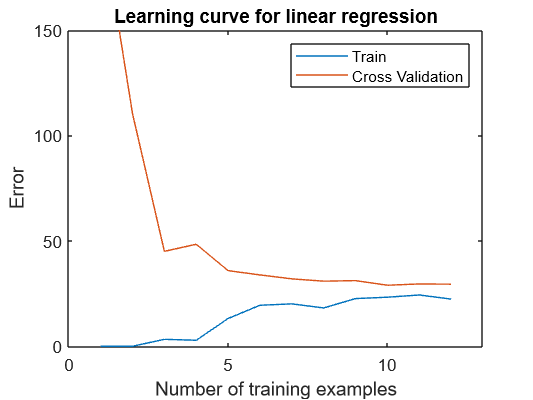


plot(1:m, error_train, 1:m, error_val);
title('Learning curve for linear regression')
legend('Train', 'Cross Validation')
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 150])


fprintf('# Training Examples\tTrain Error\tCross Validation Error\n');

# Training Examples	Train Error	Cross Validation Error


for i = 1:m
    fprintf('  \t%d\t\t%f\t%f\n', i, error_train(i), error_val(i));
end

  	1		0.000000	205.121096
  	2		0.000000	110.300366
  	3		3.286595	45.010231
  	4		2.842678	48.368911
  	5		13.154049	35.865165
  	6		19.443963	33.829962
  	7		20.098522	31.970986
  	8		18.172859	30.862446
  	9		22.609405	31.135998
  	10		23.261462	28.936207
  	11		24.317250	29.551432
  	12		22.373906	29.433818


## 3. Polynomial regression

The problem with our linear model was that it was too simple for the data and resulted in underfitting (high bias). In this part of the exercise, you will address this problem by adding more features. For use polynomial regression, our hypothesis has the form:


$$h_\theta(x) =\theta_0+\theta_1\ast (waterLevel)+\theta_2*
(waterLevel)^2+\cdots+\theta_p\ast (waterLevel)^p \\
\qquad\;=\theta_0+\theta_1 x_1+\theta_2 x_2+\cdots+\theta_p x_p \end{aligned}$$


Notice that by defining $x_1 = (\text{waterLevel}), x_2 = (\text{waterLevel)}^2,\ldots,x_p = (\text{waterLevel})^p$, we obtain a linear regression model where the features are the various powers of the original value (*waterLevel*).

    Now, you will add more features using the higher powers of the existing feature $x$ in the dataset. Your task in this part is to complete the code in `polyFeatures.`m so that the function maps the original training set `X` of size $m\times 1$into its higher powers. Specifically, when a training set $X$ of size $m\times 1$ is passed into the function, the function should return a $m\times p$ matrix `X_poly`, where column 1 holds the original values of `X`, column 2 holds the values of `X.^2`, column 3 holds the values of `X.^3`, and so on. Note that you don't have to account for the zero-th power in this function

. Now that you have a function that will map features to a higher dimension, the code in the next section will apply it to the training set, the test set, and the cross validation set (which you haven't used yet).

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 3.1 Learning Polynomial Regression

After you have completed `polyFeatures.m`, run the code below to train polynomial regression using your linear regression cost function. Keep in mind that even though we have polynomial terms in our feature vector, we are still solving a linear regression optimization problem. The polynomial terms have simply turned into features that we can use for linear regression. We are using the same cost function and gradient that you wrote for the earlier part of this exercise.

    For this part of the exercise, you will be using a polynomial of degree 8. It turns out that if we run the training directly on the projected data, it will not work well as the features would be badly scaled (e.g., an example with $x = 40$ will now have a feature $x_8 = 40^8 = 6:5\times 10^{12$) Therefore, you will need to use feature normalization. Before learning the parameters $\theta$ for the polynomial regression, code in below will first call `featureNormalize` to normalize the features of the training set, storing the `mu`, `sigma` parameters separately. We have already implemented this function for you and it is the same function from the first exercise.

p = 8;

% Map X onto Polynomial Features and Normalize
X_poly = polyFeatures(X, p);
[X_poly, mu, sigma] = featureNormalize(X_poly);  % Normalize
X_poly = [ones(m, 1), X_poly];                   % Add Ones

% Map X_poly_test and normalize (using mu and sigma)
X_poly_test = polyFeatures(Xtest, p);
X_poly_test = X_poly_test-mu; % uses implicit expansion instead of bsxfun
X_poly_test = X_poly_test./sigma; % uses implicit expansion instead of bsxfun
X_poly_test = [ones(size(X_poly_test, 1), 1), X_poly_test];         % Add Ones

% Map X_poly_val and normalize (using mu and sigma)
X_poly_val = polyFeatures(Xval, p);
X_poly_val = X_poly_val-mu; % uses implicit expansion instead of bsxfun
X_poly_val = X_poly_val./sigma; % uses implicit expansion instead of bsxfun
X_poly_val = [ones(size(X_poly_val, 1), 1), X_poly_val];           % Add Ones

fprintf('Normalized Training Example 1:\n');

Normalized Training Example 1:


fprintf('  %f  \n', X_poly(1, :));

  1.000000  
  -0.362141  
  -0.755087  
  0.182226  
  -0.706190  
  0.306618  
  -0.590878  
  0.344516  
  -0.508481  


% Train the model
lambda = 0;
[theta] = trainLinearReg(X_poly, y, lambda);

grad =   -11.2176
  -10.1019
   -1.7795
   -8.3594
    0.0332
   -6.6599
    1.2410
   -5.3929
    1.9800


grad =   -11.1881
  -10.0333
   -1.8215
   -8.2855
   -0.0193
   -6.5871
    1.1835
   -5.3229
    1.9202


grad =   -11.1292
   -9.8962
   -1.9055
   -8.1378
   -0.1242
   -6.4417
    1.0684
   -5.1828
    1.8007


grad =   -10.9525
   -9.4847
   -2.1574
   -7.6947
   -0.4389
   -6.0053
    0.7232
   -4.7627
    1.4422


grad =   -10.4223
   -8.2502
   -2.9133
   -6.3652
   -1.3830
   -4.6960
   -0.3124
   -3.5022
    0.3667


grad =    -8.8317
   -4.5468
   -5.1811
   -2.3767
   -4.2154
   -0.7684
   -3.4192
    0.2791
   -2.8598


Iteration     1 | Cost: 8.273077e+01


grad =    -4.6160
   -4.6419
   -0.3218
   -3.7678
    0.5479
   -3.0907
    1.0543
   -2.6186
    1.3484


Iteration     2 | Cost: 2.687496e+01


grad =     0.6008
    8.1577
   -8.5599
   10.1042
   -9.6223
   10.6431
  -10.0327
   10.6563
  -10.1260


grad =    -2.8599
   -0.3333
   -3.0949
    0.9017
   -2.8755
    1.5323
   -2.6778
    1.8500
   -2.5141


Iteration     3 | Cost: 1.327780e+01


grad =     0.8911
    0.0898
    0.6080
    0.2747
    0.6809
    0.1232
    0.6088
   -0.0550
    0.5412


Iteration     4 | Cost: 3.455324e+00


grad =    -9.2367
    8.3804
  -20.4996
   13.1362
  -21.1557
   15.8659
  -20.7317
   17.2767
  -20.1015


grad =    -0.1217
    0.9189
   -1.5027
    1.5608
   -1.5027
    1.6975
   -1.5253
    1.6782
   -1.5231


grad =     0.4555
    0.4464
   -0.2998
    0.8279
   -0.2583
    0.8003
   -0.3091
    0.6905
   -0.3467


Iteration     5 | Cost: 2.870493e+00


grad =    -0.1865
   -0.4419
   -0.0792
   -0.0702
    0.1174
   -0.0275
    0.1612
   -0.0643
    0.1756


Iteration     6 | Cost: 2.404364e+00


grad =    -2.3873
    0.2336
   -3.1840
    1.0491
   -2.9038
    1.5308
   -2.6488
    1.7892
   -2.4498


grad =    -0.4066
   -0.3744
   -0.3897
    0.0417
   -0.1847
    0.1284
   -0.1198
    0.1210
   -0.0869


Iteration     7 | Cost: 2.372779e+00


grad =    -0.3800
   -0.4010
   -0.3161
   -0.0171
   -0.1036
    0.0560
   -0.0364
    0.0432
   -0.0036


grad =    -0.3268
   -0.4544
   -0.1689
   -0.1348
    0.0586
   -0.0886
    0.1304
   -0.1126
    0.1631


grad =    -0.1673
   -0.6143
    0.2728
   -0.4880
    0.5454
   -0.5225
    0.6308
   -0.5798
    0.6631


Iteration     8 | Cost: 1.771555e+00


grad =     0.0935
    0.2306
   -0.2668
    0.3191
   -0.0914
    0.2570
   -0.0409
    0.1733
   -0.0187


Iteration     9 | Cost: 1.210317e+00


grad =     0.5978
    0.2096
    0.3922
   -0.1400
    0.5874
   -0.3447
    0.6415
   -0.4717
    0.6547


grad =     0.5474
    0.2117
    0.3263
   -0.0941
    0.5195
   -0.2845
    0.5733
   -0.4072
    0.5873


grad =     0.3541
    0.2197
    0.0737
    0.0818
    0.2594
   -0.0540
    0.3118
   -0.1601
    0.3293


Iteration    10 | Cost: 9.411538e-01


grad =     0.2747
    0.5965
   -0.4254
    0.4291
   -0.3080
    0.3501
   -0.2620
    0.2954
   -0.2373


Iteration    11 | Cost: 7.962055e-01


grad =    -0.1266
   -0.3005
    0.1786
   -0.7803
    0.3633
   -0.8135
    0.4621
   -0.7594
    0.5103


grad =     0.2103
    0.4527
   -0.3286
    0.2352
   -0.2004
    0.1635
   -0.1459
    0.1263
   -0.1175


Iteration    12 | Cost: 7.525931e-01


grad =     0.1919
    0.2971
   -0.1653
    0.0663
   -0.0186
   -0.0140
    0.0397
   -0.0546
    0.0672


Iteration    13 | Cost: 6.878008e-01


grad =     0.0782
    0.1775
   -0.1202
   -0.0343
    0.0234
   -0.0941
    0.0794
   -0.1189
    0.1051


grad =    -0.1142
   -0.0250
   -0.0438
   -0.2045
    0.0944
   -0.2298
    0.1466
   -0.2279
    0.1693


Iteration    14 | Cost: 5.703715e-01


grad =    -0.2513
    0.4602
   -0.6623
    0.4837
   -0.6670
    0.5578
   -0.6763
    0.6044
   -0.6769


grad =    -0.1529
    0.1120
   -0.2184
   -0.0102
   -0.1205
   -0.0075
   -0.0856
    0.0070
   -0.0696


Iteration    15 | Cost: 5.372258e-01


grad =    -0.1031
    0.0783
   -0.1292
   -0.0252
   -0.0634
   -0.0144
   -0.0516
    0.0043
   -0.0503


grad =    -0.0214
    0.0230
    0.0173
   -0.0499
    0.0306
   -0.0258
    0.0044
   -0.0003
   -0.0186


Iteration    16 | Cost: 4.496190e-01


grad =     0.7622
    1.5702
   -1.6949
    1.9536
   -1.9652
    2.1337
   -2.0984
    2.1942
   -2.1492


grad =     0.0570
    0.1777
   -0.1539
    0.1504
   -0.1690
    0.1901
   -0.2058
    0.2192
   -0.2317


grad =     0.0014
    0.0679
   -0.0324
    0.0083
   -0.0274
    0.0369
   -0.0567
    0.0635
   -0.0805


Iteration    17 | Cost: 4.470743e-01


grad =     0.0238
    0.0577
   -0.0229
    0.0002
   -0.0179
    0.0291
   -0.0476
    0.0556
   -0.0718


grad =     0.0687
    0.0371
   -0.0038
   -0.0158
    0.0010
    0.0136
   -0.0294
    0.0398
   -0.0543


grad =     0.1477
    0.0010
    0.0299
   -0.0440
    0.0344
   -0.0137
    0.0025
    0.0121
   -0.0234


Iteration    18 | Cost: 4.304819e-01


grad =     0.1105
    0.0011
    0.0130
   -0.0181
    0.0130
    0.0167
   -0.0208
    0.0416
   -0.0470


grad =     0.0361
    0.0012
   -0.0207
    0.0336
   -0.0299
    0.0776
   -0.0676
    0.1007
   -0.0942


Iteration    19 | Cost: 3.725024e-01


grad =    -0.1429
   -0.6778
    0.7181
   -0.7639
    0.8180
   -0.7831
    0.8190
   -0.7868
    0.8025


grad =     0.0178
   -0.0684
    0.0551
   -0.0482
    0.0571
   -0.0107
    0.0234
    0.0096
   -0.0022


Iteration    20 | Cost: 3.673952e-01


grad =    -0.0234
   -0.0622
    0.0542
   -0.0467
    0.0638
   -0.0156
    0.0348
   -0.0003
    0.0123


grad =    -0.0996
   -0.0507
    0.0525
   -0.0439
    0.0762
   -0.0248
    0.0560
   -0.0188
    0.0390


Iteration    21 | Cost: 3.528220e-01


grad =    -0.0648
    0.1794
   -0.2106
    0.2240
   -0.2010
    0.2509
   -0.2191
    0.2542
   -0.2296


grad =    -0.0896
    0.0153
   -0.0230
    0.0330
   -0.0034
    0.0543
   -0.0229
    0.0596
   -0.0381


Iteration    22 | Cost: 3.486394e-01


grad =    -0.0388
    0.0063
   -0.0244
    0.0195
    0.0034
    0.0380
   -0.0109
    0.0417
   -0.0228


grad =     0.0280
   -0.0055
   -0.0262
    0.0018
    0.0122
    0.0166
    0.0050
    0.0182
   -0.0026


Iteration    23 | Cost: 3.389543e-01


grad =    -0.0907
   -0.2333
    0.2345
   -0.2929
    0.3167
   -0.3066
    0.3281
   -0.3154
    0.3272


grad = 9×1
    0.0114
   -0.0373
    0.0102
   -0.0394
    0.0548
   -0.0285
    0.0501
   -0.0285
    0.0435


Iteration    24 | Cost: 3.376007e-01


grad = 9×1
   -0.0077
   -0.0284
    0.0025
   -0.0315
    0.0472
   -0.0215
    0.0433
   -0.0221
    0.0373


grad = 9×1
   -0.0460
   -0.0104
   -0.0129
   -0.0157
    0.0322
   -0.0074
    0.0296
   -0.0093
    0.0249


Iteration    25 | Cost: 3.318251e-01


grad = 9×1
    0.0220
    0.0992
   -0.1364
    0.1196
   -0.1099
    0.1388
   -0.1187
    0.1404
   -0.1246


grad = 9×1
   -0.0277
    0.0191
   -0.0461
    0.0207
   -0.0061
    0.0319
   -0.0103
    0.0310
   -0.0153


Iteration    26 | Cost: 3.307322e-01


grad = 9×1
    0.0010
    0.0084
   -0.0357
    0.0093
    0.0043
    0.0208
   -0.0002
    0.0204
   -0.0055


grad = 9×1
    0.0344
   -0.0040
   -0.0235
   -0.0040
    0.0164
    0.0078
    0.0116
    0.0080
    0.0060


Iteration    27 | Cost: 3.283683e-01


grad = 9×1
    0.0225
   -0.0189
   -0.0039
   -0.0193
    0.0322
   -0.0060
    0.0249
   -0.0045
    0.0177


grad = 9×1
   -0.0013
   -0.0489
    0.0354
   -0.0498
    0.0638
   -0.0338
    0.0516
   -0.0294
    0.0411


Iteration    28 | Cost: 3.185148e-01


grad = 9×1
   -0.0251
    0.0583
   -0.0757
    0.0836
   -0.0735
    0.1125
   -0.0961
    0.1222
   -0.1101


grad = 9×1
   -0.0136
    0.0068
   -0.0223
    0.0195
   -0.0075
    0.0422
   -0.0252
    0.0494
   -0.0375


Iteration    29 | Cost: 3.148289e-01


grad = 9×1
   -0.0359
    0.0371
   -0.0465
    0.0586
   -0.0498
    0.0889
   -0.0754
    0.1007
   -0.0911


Iteration    30 | Cost: 3.108240e-01


grad = 9×1
   -0.0427
   -0.0020
    0.0013
    0.0119
   -0.0035
    0.0417
   -0.0305
    0.0549
   -0.0476


Iteration    31 | Cost: 3.053698e-01


grad = 9×1
    0.0218
   -0.0942
    0.0919
   -0.1083
    0.1185
   -0.0935
    0.1054
   -0.0873
    0.0941


grad = 9×1
   -0.0265
   -0.0251
    0.0240
   -0.0182
    0.0271
    0.0078
    0.0035
    0.0192
   -0.0121


Iteration    32 | Cost: 3.044467e-01


grad = 9×1
   -0.0106
   -0.0097
    0.0058
   -0.0029
    0.0101
    0.0226
   -0.0120
    0.0333
   -0.0265


grad = 9×1
    0.0131
    0.0132
   -0.0213
    0.0200
   -0.0152
    0.0446
   -0.0352
    0.0544
   -0.0479


Iteration    33 | Cost: 3.021439e-01


grad = 9×1
    0.0471
   -0.0208
    0.0132
   -0.0312
    0.0343
   -0.0147
    0.0221
   -0.0086
    0.0132


Iteration    34 | Cost: 3.006816e-01


grad = 9×1
    0.0911
    0.0356
   -0.0542
   -0.0071
    0.0006
   -0.0102
    0.0118
   -0.0161
    0.0177


grad = 9×1
    0.0539
   -0.0120
    0.0028
   -0.0274
    0.0290
   -0.0140
    0.0205
   -0.0098
    0.0139


Iteration    35 | Cost: 3.003235e-01


grad = 9×1
    0.0469
   -0.0014
   -0.0085
   -0.0147
    0.0162
   -0.0005
    0.0071
    0.0040
    0.0005


grad = 9×1
    0.0349
    0.0170
   -0.0279
    0.0074
   -0.0059
    0.0229
   -0.0159
    0.0276
   -0.0227


Iteration    36 | Cost: 2.993482e-01


grad = 9×1
    0.0006
    0.0062
   -0.0139
   -0.0060
    0.0094
    0.0083
   -0.0003
    0.0126
   -0.0072


Iteration    37 | Cost: 2.981264e-01


grad = 9×1
    0.0309
   -0.0606
    0.0577
   -0.0859
    0.0899
   -0.0763
    0.0832
   -0.0731
    0.0768


grad = 9×1
    0.0069
   -0.0077
    0.0011
   -0.0226
    0.0261
   -0.0093
    0.0170
   -0.0053
    0.0103


Iteration    38 | Cost: 2.979233e-01


grad = 9×1
    0.0102
   -0.0043
   -0.0029
   -0.0184
    0.0216
   -0.0048
    0.0123
   -0.0006
    0.0056


grad = 9×1
    0.0168
    0.0025
   -0.0108
   -0.0099
    0.0125
    0.0044
    0.0029
    0.0087
   -0.0038


grad = 9×1
    0.0365
    0.0230
   -0.0344
    0.0156
   -0.0148
    0.0318
   -0.0252
    0.0367
   -0.0319


Iteration    39 | Cost: 2.957706e-01


grad = 9×1
    0.0525
    0.0025
   -0.0125
   -0.0083
    0.0088
    0.0066
   -0.0008
    0.0111
   -0.0071


grad = 9×1
    0.0844
   -0.0387
    0.0313
   -0.0562
    0.0560
   -0.0439
    0.0481
   -0.0401
    0.0425


Iteration    40 | Cost: 2.897885e-01


grad = 9×1
    0.1146
   -0.0297
    0.0210
   -0.0424
    0.0396
   -0.0288
    0.0310
   -0.0249
    0.0263


grad = 9×1
    0.1749
   -0.0116
    0.0004
   -0.0149
    0.0067
    0.0015
   -0.0032
    0.0055
   -0.0061


Iteration    41 | Cost: 2.699324e-01


grad = 9×1
    0.0546
    0.0179
   -0.0211
    0.0204
   -0.0251
    0.0370
   -0.0366
    0.0395
   -0.0383


Iteration    42 | Cost: 2.469104e-01


grad = 9×1
   -0.1216
   -0.4148
    0.4660
   -0.5107
    0.5277
   -0.5335
    0.5379
   -0.5427
    0.5399


grad = 9×1
    0.0370
   -0.0254
    0.0276
   -0.0327
    0.0302
   -0.0201
    0.0209
   -0.0187
    0.0195


Iteration    43 | Cost: 2.457101e-01


grad = 9×1
   -0.0475
   -0.0356
    0.0444
   -0.0498
    0.0513
   -0.0410
    0.0440
   -0.0416
    0.0436


grad = 9×1
    0.0015
   -0.0297
    0.0347
   -0.0399
    0.0390
   -0.0289
    0.0306
   -0.0284
    0.0296


Iteration    44 | Cost: 2.450191e-01


grad = 9×1
   -0.0035
   -0.0043
    0.0071
   -0.0097
    0.0082
    0.0030
   -0.0011
    0.0038
   -0.0021


Iteration    45 | Cost: 2.442552e-01


grad = 9×1
    0.0310
    0.0113
   -0.0134
    0.0020
   -0.0067
    0.0119
   -0.0118
    0.0108
   -0.0100


grad = 9×1
    0.0173
    0.0051
   -0.0053
   -0.0026
   -0.0008
    0.0084
   -0.0076
    0.0080
   -0.0068


Iteration    46 | Cost: 2.438372e-01


grad = 9×1
    0.0105
   -0.0202
    0.0226
   -0.0376
    0.0349
   -0.0312
    0.0318
   -0.0336
    0.0342


grad = 9×1
    0.0146
   -0.0052
    0.0061
   -0.0169
    0.0138
   -0.0078
    0.0085
   -0.0090
    0.0099


Iteration    47 | Cost: 2.436664e-01


grad = 9×1
    0.0070
   -0.0003
    0.0010
   -0.0129
    0.0098
   -0.0045
    0.0054
   -0.0063
    0.0074


grad = 9×1
   -0.0060
    0.0082
   -0.0077
   -0.0059
    0.0029
    0.0011
    0.0000
   -0.0017
    0.0031


Iteration    48 | Cost: 2.432017e-01


grad = 9×1
   -0.0011
    0.0127
   -0.0140
    0.0011
   -0.0041
    0.0085
   -0.0071
    0.0056
   -0.0038


grad = 9×1
    0.0088
    0.0218
   -0.0266
    0.0152
   -0.0182
    0.0234
   -0.0212
    0.0201
   -0.0176


grad = 9×1
    0.0288
    0.0402
   -0.0520
    0.0436
   -0.0466
    0.0535
   -0.0499
    0.0496
   -0.0455


Iteration    49 | Cost: 2.399209e-01


grad = 9×1
    0.0537
   -0.0089
   -0.0063
   -0.0047
    0.0051
    0.0017
    0.0048
   -0.0048
    0.0106


Iteration    50 | Cost: 2.366051e-01


grad = 9×1
   -0.0320
   -0.0099
   -0.0008
    0.0015
    0.0083
    0.0065
    0.0074
   -0.0024
    0.0134


Iteration    51 | Cost: 2.346713e-01


grad = 9×1
   -0.1642
    0.4011
   -0.4781
    0.5782
   -0.5515
    0.6172
   -0.5723
    0.6035
   -0.5628


grad = 9×1
   -0.0452
    0.0312
   -0.0485
    0.0591
   -0.0477
    0.0675
   -0.0506
    0.0582
   -0.0442


grad = 9×1
   -0.0335
   -0.0052
   -0.0063
    0.0081
    0.0018
    0.0135
    0.0007
    0.0045
    0.0068


Iteration    52 | Cost: 2.346336e-01


grad = 9×1
   -0.0319
   -0.0058
   -0.0058
    0.0075
    0.0023
    0.0129
    0.0012
    0.0039
    0.0073


grad = 9×1
   -0.0286
   -0.0069
   -0.0050
    0.0062
    0.0034
    0.0116
    0.0023
    0.0027
    0.0084


grad = 9×1
   -0.0188
   -0.0101
   -0.0023
    0.0024
    0.0064
    0.0077
    0.0056
   -0.0011
    0.0118


grad = 9×1
    0.0057
   -0.0183
    0.0042
   -0.0070
    0.0141
   -0.0018
    0.0138
   -0.0105
    0.0202


Iteration    53 | Cost: 2.337306e-01


grad = 9×1
    0.0396
    0.0435
   -0.0662
    0.0671
   -0.0652
    0.0776
   -0.0679
    0.0707
   -0.0616


grad = 9×1
    0.0126
   -0.0058
   -0.0100
    0.0080
   -0.0020
    0.0142
   -0.0027
    0.0059
    0.0036


Iteration    54 | Cost: 2.335479e-01


grad = 9×1
    0.0120
   -0.0053
   -0.0099
    0.0079
   -0.0020
    0.0140
   -0.0028
    0.0058
    0.0035


grad = 9×1
    0.0109
   -0.0044
   -0.0097
    0.0075
   -0.0022
    0.0136
   -0.0030
    0.0055
    0.0034


grad = 9×1
    0.0076
   -0.0015
   -0.0092
    0.0065
   -0.0025
    0.0122
   -0.0035
    0.0046
    0.0028


grad = 9×1
   -0.0024
    0.0071
   -0.0074
    0.0034
   -0.0035
    0.0081
   -0.0050
    0.0018
    0.0012


Iteration    55 | Cost: 2.271682e-01


grad = 9×1
    0.0929
   -0.9104
    0.9247
   -1.0566
    1.0299
   -1.0910
    1.0559
   -1.0949
    1.0609


grad = 9×1
    0.0071
   -0.0847
    0.0858
   -0.1026
    0.0998
   -0.1018
    0.1011
   -0.1078
    0.1072


grad = 9×1
   -0.0015
   -0.0021
    0.0019
   -0.0072
    0.0068
   -0.0029
    0.0056
   -0.0091
    0.0118


Iteration    56 | Cost: 2.271416e-01


grad = 9×1
    0.0036
   -0.0177
    0.0150
   -0.0233
    0.0205
   -0.0184
    0.0192
   -0.0238
    0.0251


grad = 9×1
   -0.0001
   -0.0064
    0.0055
   -0.0116
    0.0105
   -0.0071
    0.0094
   -0.0131
    0.0154


Iteration    57 | Cost: 2.271282e-01


grad = 9×1
    0.0001
   -0.0054
    0.0042
   -0.0103
    0.0091
   -0.0056
    0.0078
   -0.0116
    0.0139


grad = 9×1
    0.0004
   -0.0034
    0.0017
   -0.0076
    0.0061
   -0.0027
    0.0047
   -0.0085
    0.0108


grad = 9×1
    0.0015
    0.0027
   -0.0057
    0.0003
   -0.0026
    0.0062
   -0.0045
    0.0007
    0.0014


Iteration    58 | Cost: 2.269971e-01


grad = 9×1
    0.0019
   -0.0024
    0.0001
   -0.0038
    0.0018
    0.0029
   -0.0012
   -0.0020
    0.0039


grad = 9×1
    0.0027
   -0.0112
    0.0099
   -0.0109
    0.0092
   -0.0028
    0.0044
   -0.0065
    0.0083


Iteration    59 | Cost: 2.266699e-01


grad = 9×1
    0.0014
    0.0139
   -0.0149
    0.0259
   -0.0270
    0.0401
   -0.0377
    0.0393
   -0.0367


grad = 9×1
    0.0024
   -0.0053
    0.0041
   -0.0023
    0.0007
    0.0072
   -0.0055
    0.0042
   -0.0022


Iteration    60 | Cost: 2.265934e-01


grad = 9×1
   -0.0001
   -0.0046
    0.0053
   -0.0022
    0.0016
    0.0071
   -0.0047
    0.0040
   -0.0016


grad = 9×1
   -0.0050
   -0.0031
    0.0076
   -0.0018
    0.0035
    0.0070
   -0.0033
    0.0035
   -0.0005


grad = 9×1
   -0.0196
    0.0013
    0.0145
   -0.0007
    0.0089
    0.0064
    0.0010
    0.0022
    0.0029


Iteration    61 | Cost: 2.256577e-01


grad = 9×1
   -0.0071
    0.0119
   -0.0050
    0.0109
   -0.0107
    0.0196
   -0.0177
    0.0167
   -0.0149


grad = 9×1
    0.0056
    0.0226
   -0.0249
    0.0227
   -0.0306
    0.0331
   -0.0367
    0.0313
   -0.0330


Iteration    62 | Cost: 2.242699e-01


grad = 9×1
    0.0397
   -0.0029
   -0.0181
   -0.0121
   -0.0158
   -0.0018
   -0.0168
   -0.0015
   -0.0104


Iteration    63 | Cost: 2.232737e-01


grad = 9×1
    0.0086
   -0.0275
    0.0344
   -0.0514
    0.0404
   -0.0485
    0.0396
   -0.0515
    0.0449


grad = 9×1
    0.0210
   -0.0177
    0.0134
   -0.0357
    0.0180
   -0.0299
    0.0171
   -0.0315
    0.0228


Iteration    64 | Cost: 2.224402e-01


grad = 9×1
   -0.0012
    0.0095
    0.0011
   -0.0085
    0.0015
   -0.0041
   -0.0015
   -0.0072
    0.0032


Iteration    65 | Cost: 2.214499e-01


grad = 9×1
    0.0438
    0.0409
   -0.0774
    0.0551
   -0.0883
    0.0751
   -0.0952
    0.0794
   -0.0912


grad = 9×1
    0.0044
    0.0134
   -0.0087
   -0.0006
   -0.0097
    0.0058
   -0.0132
    0.0036
   -0.0086


Iteration    66 | Cost: 2.213459e-01


grad = 9×1
    0.0071
    0.0046
   -0.0020
   -0.0088
   -0.0026
   -0.0020
   -0.0061
   -0.0038
   -0.0016


Iteration    67 | Cost: 2.211932e-01


grad = 9×1
    0.0006
    0.0059
    0.0020
   -0.0079
    0.0007
   -0.0018
   -0.0035
   -0.0042
    0.0005


grad = 9×1
   -0.0104
    0.0079
    0.0087
   -0.0064
    0.0062
   -0.0015
    0.0009
   -0.0049
    0.0041


Iteration    68 | Cost: 2.209154e-01


grad = 9×1
   -0.0127
    0.0281
   -0.0128
    0.0207
   -0.0193
    0.0277
   -0.0264
    0.0248
   -0.0239


grad = 9×1
   -0.0117
    0.0190
   -0.0031
    0.0085
   -0.0078
    0.0146
   -0.0141
    0.0114
   -0.0113


Iteration    69 | Cost: 2.207625e-01


grad = 9×1
   -0.0103
    0.0159
   -0.0017
    0.0069
   -0.0066
    0.0135
   -0.0131
    0.0106
   -0.0104


grad = 9×1
   -0.0075
    0.0096
    0.0011
    0.0037
   -0.0040
    0.0113
   -0.0110
    0.0088
   -0.0086


grad = 9×1
    0.0002
   -0.0077
    0.0088
   -0.0050
    0.0028
    0.0054
   -0.0053
    0.0040
   -0.0037


Iteration    70 | Cost: 2.194667e-01


grad = 9×1
    0.0097
    0.0098
   -0.0102
    0.0101
   -0.0061
    0.0141
   -0.0080
    0.0074
   -0.0027


Iteration    71 | Cost: 2.185374e-01


grad = 9×1
   -0.0231
   -0.1854
    0.1807
   -0.2265
    0.2301
   -0.2436
    0.2475
   -0.2591
    0.2604


grad = 9×1
    0.0064
   -0.0097
    0.0089
   -0.0136
    0.0175
   -0.0116
    0.0175
   -0.0192
    0.0236


grad = 9×1
    0.0086
    0.0037
   -0.0043
    0.0027
    0.0013
    0.0061
   -0.0000
   -0.0009
    0.0055


Iteration    72 | Cost: 2.184968e-01


grad = 9×1
    0.0051
    0.0017
   -0.0038
    0.0010
    0.0016
    0.0049
    0.0002
   -0.0018
    0.0058


grad = 9×1
   -0.0021
   -0.0022
   -0.0029
   -0.0022
    0.0023
    0.0025
    0.0008
   -0.0035
    0.0063


Iteration    73 | Cost: 2.183417e-01


grad = 9×1
   -0.0024
    0.0141
   -0.0202
    0.0186
   -0.0189
    0.0254
   -0.0222
    0.0203
   -0.0174


grad = 9×1
   -0.0022
    0.0040
   -0.0095
    0.0056
   -0.0057
    0.0112
   -0.0079
    0.0056
   -0.0027


Iteration    74 | Cost: 2.182956e-01


grad = 9×1
   -0.0018
    0.0041
   -0.0090
    0.0062
   -0.0061
    0.0121
   -0.0088
    0.0068
   -0.0039


grad = 9×1
   -0.0011
    0.0043
   -0.0080
    0.0073
   -0.0068
    0.0140
   -0.0105
    0.0092
   -0.0063


grad = 9×1
    0.0005
    0.0049
   -0.0056
    0.0100
   -0.0085
    0.0185
   -0.0147
    0.0149
   -0.0119


Iteration    75 | Cost: 2.179413e-01


grad = 9×1
    0.0014
   -0.0295
    0.0335
   -0.0305
    0.0330
   -0.0235
    0.0270
   -0.0269
    0.0291


grad = 9×1
    0.0008
   -0.0059
    0.0067
   -0.0028
    0.0046
    0.0053
   -0.0015
    0.0017
    0.0011


Iteration    76 | Cost: 2.178295e-01


grad = 9×1
   -0.0001
   -0.0061
    0.0049
   -0.0042
    0.0039
    0.0036
   -0.0015
    0.0001
    0.0017


grad = 9×1
   -0.0020
   -0.0065
    0.0013
   -0.0070
    0.0025
    0.0003
   -0.0013
   -0.0031
    0.0029


grad = 9×1
   -0.0054
   -0.0071
   -0.0050
   -0.0120
   -0.0000
   -0.0054
   -0.0009
   -0.0088
    0.0049


Iteration    77 | Cost: 2.171022e-01


grad = 9×1
    0.0091
    0.0956
   -0.0766
    0.0925
   -0.0826
    0.0965
   -0.0876
    0.0895
   -0.0830


grad = 9×1
   -0.0038
    0.0041
   -0.0129
   -0.0005
   -0.0091
    0.0057
   -0.0104
    0.0020
   -0.0047


Iteration    78 | Cost: 2.170226e-01


grad = 9×1
   -0.0009
    0.0063
   -0.0073
   -0.0006
   -0.0037
    0.0041
   -0.0055
   -0.0005
   -0.0002


grad = 9×1
    0.0025
    0.0089
   -0.0009
   -0.0007
    0.0023
    0.0023
    0.0001
   -0.0034
    0.0050


Iteration    79 | Cost: 2.168522e-01


grad = 9×1
    0.0024
    0.0044
    0.0033
   -0.0046
    0.0055
   -0.0008
    0.0025
   -0.0059
    0.0069


grad = 9×1
    0.0023
   -0.0047
    0.0117
   -0.0124
    0.0119
   -0.0070
    0.0074
   -0.0108
    0.0108


Iteration    80 | Cost: 2.160925e-01


grad = 9×1
    0.0001
    0.0278
   -0.0285
    0.0306
   -0.0358
    0.0411
   -0.0432
    0.0397
   -0.0408


grad = 9×1
    0.0015
    0.0066
   -0.0022
    0.0025
   -0.0047
    0.0097
   -0.0101
    0.0067
   -0.0071


Iteration    81 | Cost: 2.159153e-01


grad = 9×1
   -0.0023
    0.0116
   -0.0140
    0.0127
   -0.0199
    0.0231
   -0.0269
    0.0222
   -0.0245


Iteration    82 | Cost: 2.157734e-01


grad = 9×1
   -0.0050
    0.0037
   -0.0095
    0.0060
   -0.0163
    0.0179
   -0.0239
    0.0181
   -0.0220


grad = 9×1
   -0.0098
   -0.0105
   -0.0013
   -0.0060
   -0.0098
    0.0084
   -0.0185
    0.0108
   -0.0174


Iteration    83 | Cost: 2.152789e-01


grad = 9×1
   -0.0003
   -0.0254
    0.0328
   -0.0315
    0.0290
   -0.0234
    0.0214
   -0.0245
    0.0226


grad = 9×1
   -0.0049
   -0.0182
    0.0162
   -0.0191
    0.0101
   -0.0079
    0.0020
   -0.0073
    0.0031


Iteration    84 | Cost: 2.150248e-01


grad = 9×1
    0.0020
   -0.0021
    0.0117
   -0.0054
    0.0053
    0.0031
   -0.0031
    0.0016
   -0.0020


Iteration    85 | Cost: 2.147027e-01


grad = 9×1
   -0.0064
    0.0079
   -0.0162
    0.0085
   -0.0210
    0.0196
   -0.0272
    0.0195
   -0.0244


grad = 9×1
   -0.0026
    0.0034
   -0.0037
    0.0023
   -0.0092
    0.0122
   -0.0164
    0.0115
   -0.0143


Iteration    86 | Cost: 2.145627e-01


grad = 9×1
   -0.0058
   -0.0056
   -0.0002
   -0.0085
   -0.0028
    0.0011
   -0.0082
    0.0004
   -0.0052


Iteration    87 | Cost: 2.143724e-01


grad = 9×1
    0.0007
   -0.0023
    0.0090
   -0.0087
    0.0066
   -0.0020
    0.0008
   -0.0045
    0.0034


Iteration    88 | Cost: 2.142106e-01


grad = 9×1
    0.0050
    0.0231
   -0.0109
    0.0186
   -0.0156
    0.0250
   -0.0222
    0.0215
   -0.0198


grad = 9×1
    0.0021
    0.0058
    0.0026
   -0.0000
   -0.0005
    0.0066
   -0.0065
    0.0038
   -0.0040


Iteration    89 | Cost: 2.141660e-01


grad = 9×1
    0.0029
    0.0077
    0.0018
    0.0012
   -0.0008
    0.0072
   -0.0064
    0.0039
   -0.0037


grad = 9×1
    0.0045
    0.0114
    0.0000
    0.0035
   -0.0013
    0.0083
   -0.0063
    0.0042
   -0.0031


After learning the parameters $\theta$, the code below will generate two plots (Figures 4,5) for polynomial regression with $\lambda = 0$. 

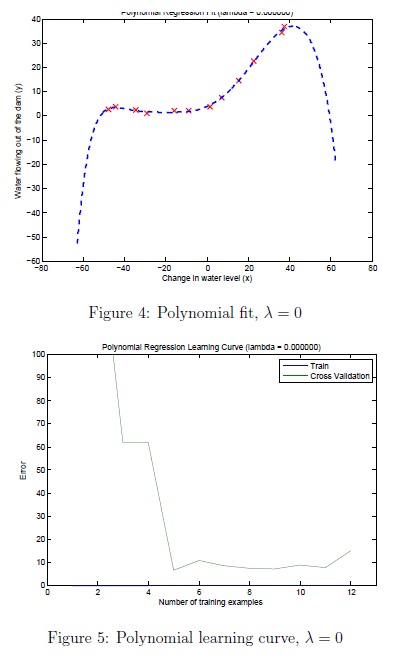

From Figure 4, you should see that the polynomial fit is able to follow the datapoints very well - thus, obtaining a low training error. However, the polynomial fit is very complex and even drops off at the extremes. This is an indicator that the polynomial regression model is overfitting the training data and will not generalize well.

% Plot training data and fit
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));
[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);
plot(1:m, error_train, 1:m, error_val);
title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

    To better understand the problems with the unregularized $\lambda=0$ model, you can see that the learning curve (Figure 5) shows the same effect where the low training error is low, but the cross validation error is high. There is a gap between the training and cross validation errors, indicating a high variance problem. One way to combat the overfitting (high-variance) problem is to add regularization to the model. In the next section, you will get to try different $\lambda$ parameters to see how regularization can lead to a better model.

### 3.2 Optional (ungraded) exercise: Adjusting the regularization parameter

In this section, you will get to observe how the regularization parameter affects the bias-variance of regularized polynomial regression. You should now modify the the `lambda` parameter in the code below and try $\lambda = 1,\; 100$. 

% Choose the value of lambda
lambda = 1;
[theta] = trainLinearReg(X_poly, y, lambda);

% Plot training data and fit
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));
[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);
plot(1:m, error_train, 1:m, error_val);
title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

For each of these values, the code should generate a polynomial fit to the data and also a learning curve.

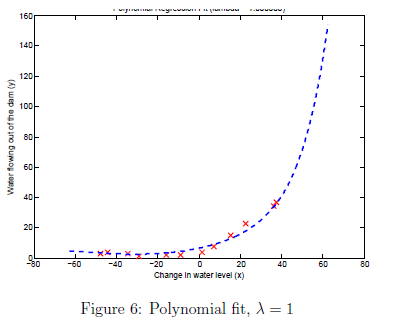

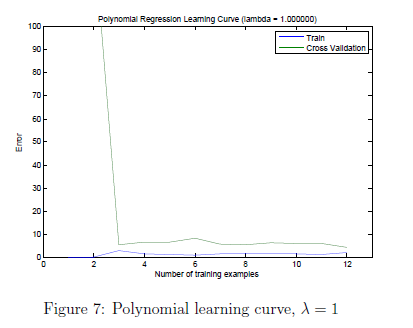

    For $\lambda= 1$, you should see a polynomial fit that follows the data trend well (Figure 6) and a learning curve (Figure 7) showing that both the cross validation and training error converge to a relatively low value. This shows the $\lambda= 1$ regularized polynomial regression model does not have the high bias or high-variance problems. In effect, it achieves a good trade-off between bias and variance.

    For $\lambda= 100$, you should see a polynomial fit (Figure 8) that does not follow the data well. In this case, there is too much regularization and the model is unable to fit the training data.

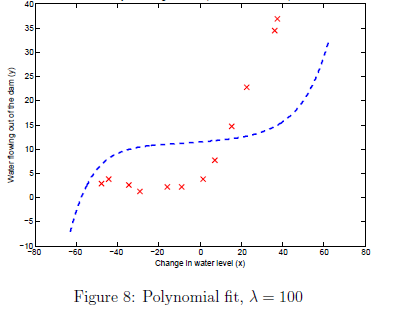

### 3.3 Selecting lambda using a cross validation set

From the previous parts of the exercise, you observed that the value of $\lambda$ can significantly affect the results of regularized polynomial regression on the training and cross validation set. In particular, a model without regularization ($\lambda = 0$) fits the training set well, but does not generalize. Conversely, a model with too much regularization ($\lambda=100$)  does not fit the training set and testing set well. A good choice of $\lambda$ (e.g. $\lambda=1$) can provide a good fit to the data.

    In this section, you will implement an automated method to select the parameter. Concretely, you will use a cross validation set to evaluate how good each $\lambda$ value is. After selecting the best $\lambda$ value using the cross validation set, we can then evaluate the model on the test set to estimate how well the model will perform on actual unseen data. Your task is to complete the code in `validationCurve.m`. Specifically, you should should use the `trainLinearReg` function to train the model using different values of $\lambda$ and compute the training error and cross validation error. The function will try $\lambda$ in the following range: {0, 0.001, 0.003, 0.01, 0.03, 0.1, 0.3, 1, 3, 10}.

    After you have completed the code, the code below will run your function and plot a cross validation curve of error v.s $\lambda$ that allows you select which $\lambda$ parameter to use. You should see a plot similar to Figure 9. 

[lambda_vec, error_train, error_val] = validationCurve(X, y, Xval, yval);
plot(lambda_vec, error_train, lambda_vec, error_val);
legend('Train', 'Cross Validation');
xlabel('lambda');
ylabel('Error');
for i = 1:length(lambda_vec)
    if i == 1
        fprintf('lambda\t\tTrain Error\tValidation Error\n');
    end
    fprintf('%f\t%f\t%f\n',lambda_vec(i), error_train(i), error_val(i));
end

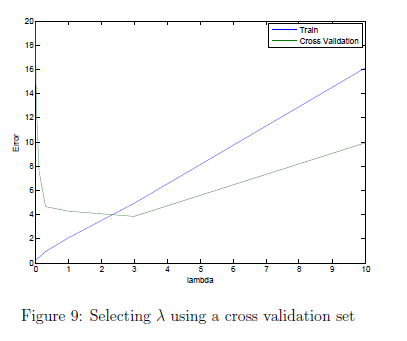

In this figure, we can see that the best value of $\lambda$ is around 3. Due to randomness in the training and validation splits of the dataset, the cross validation error can sometimes be lower than the training error. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 3.4 Optional (ungraded) exercise: Computing test set error

In the previous part of the exercise, you implemented code to compute the cross validation error for various values of the regularization parameter $\lambda$. However, to get a better indication of the model's performance in the real world, it is important to evaluate the 'final' model on a test set that was not used in any part of training (that is, it was neither used to select the $\lambda$ parameters, nor to learn the model parameters $\theta$).

    For this optional (ungraded) exercise, you should compute the test error using the best value of $\lambda$ you found. In our cross validation, we obtained a test error of 3.8599 for $\lambda= 3.$ You do not need to submit any solutions for this optional (ungraded) exercise.

%%%%%%%%% Add your code to compute the test error below %%%%%%%%%%%



### 3.5 Optional (ungraded) exercise: Plotting learning curves with randomly selected examples

In practice, especially for small training sets, when you plot learning curves to debug your algorithms, it is often helpful to average across multiple sets of randomly selected examples to determine the training error and cross validation error. Concretely, to determine the training error and cross validation error for $i$ examples, you should first randomly select $i$ examples from the training set and $i$ examples from the cross validation set. You will then learn the parameters $\theta$ using the randomly chosen training set and evaluate the parameters $\theta$ on the randomly chosen training set and cross validation set. The above steps should then be repeated multiple times (say 50) and the averaged error should be used to determine the training error and cross validation error for $i$ examples.

     For this optional (ungraded) exercise, you should implement the above strategy for computing the learning curves in `learningCurve.m` and use the code below to call your modified function and generate the plot.

lambda = 0.01;
[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);
plot(1:m, error_train, 1:m, error_val);

title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

For reference, Figure 10 shows the learning curve we obtained for polynomial regression with $\lambda= 0.01$. 

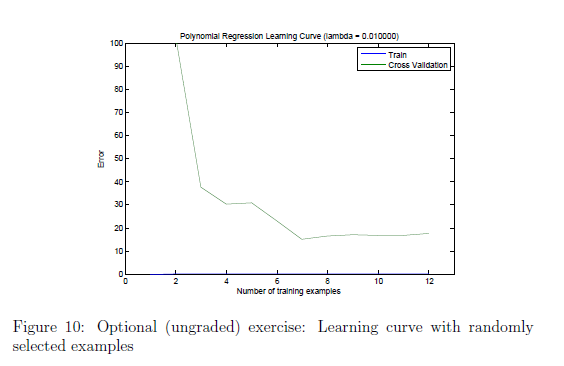

Your figure may differ slightly due to the random selection of examples. 

*You do not need to submit any solutions for this optional (ungraded) exercise.*

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

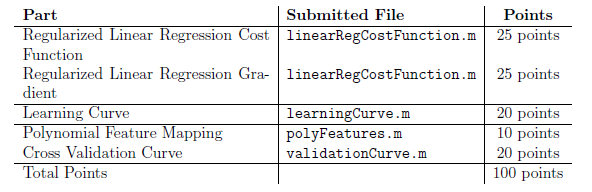

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.